optoChan_0Ind = 133;
facemotionThresh = 1000;

checkDOWNDetection = false;

serverPath = "G:\ChR2_dual_summer_2023";

## Animal 6560

Day 4 - Session A

basepath = char(serverPath + '\6560\JR_23_08_17_ChR2_dual_animal_6560_session_A\JR_23_08_17_ChR2_dual_animal_6560_session_A_230817_112238');

spikes = bz_GetSpikes('basepath', basepath,'spikeGroups',1);

loading spikes from cellinfo file..


spikesMU = GetMUA('basepath', basepath,'spikeGroups',1);

loading mua from cellinfo file..


spikesAll = SSTnNOS.concatenateSpikeStructs(spikes, spikesMU);

lfp = bz_GetLFP(0:63, 'basepath',basepath);

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


lfp.data = lfp.data - median(lfp.data,2);

channelDepths = layerLocalization(basepath);

% Choose a channel in L5
[~, L5ChanInd] = min(abs(channelDepths(1,:) - 700));
co = getChannelOrder2('H3');
L5Chan = co(L5ChanInd) - 1;

SW = DetectSlowWaves(basepath, 'lfp', lfp, 'spikes', spikesAll, 'DetectionChannel', L5Chan, 'forceReload', false,...
    'joinwindur',0.005, 'noPrompts',true);

Slow Oscillation already Detected, loading JR_23_08_17_ChR2_dual_animal_6560_session_A_230817_112238.SlowWaves.events.mat



% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(basepath, optoChan_0Ind);

Loading Channels 133 (0-indexing, a la Neuroscope)
loading LFP file...


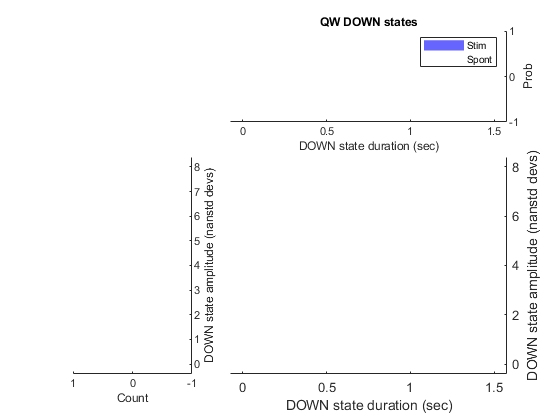

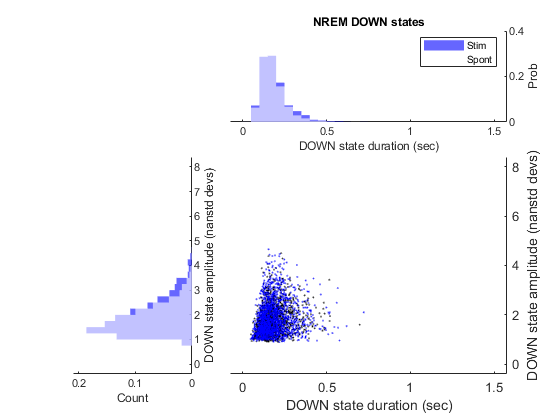

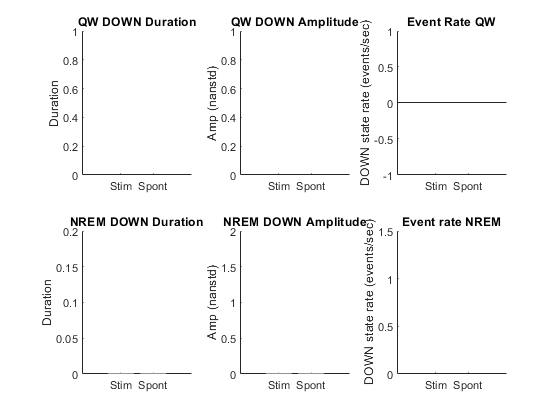

loading spikes from cellinfo file..
loading spikes from cellinfo file..
loading spikes from cellinfo file..
loading spikes from cellinfo file..


DOWNwin = 1×60 logical array
   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


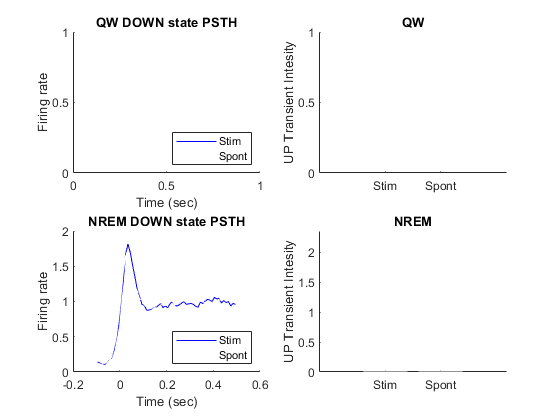

optoInts = getOptoInts(basepath, optostim, facemotionThresh);

Animal6560.ipsi = analyzeDOWNStates(basepath, SW, spikes, optostim, optoInts);

if checkDOWNDetection
    JR_EventExplorer(basepath, SW, 'spikes', spikesAll, 'lfp', dropLFPChans(lfp, L5Chan))
end

Day 2 - Session A

basepath = char(serverPath + '\6560\JR_23_08_15_ChR2_dual_animal_6560_session_A\JR_23_08_15_ChR2_dual_animal_6560_session_A_230815_100405');

spikes = bz_GetSpikes('basepath', basepath,'spikeGroups',1);

loading spikes from cellinfo file..


spikesMU = GetMUA('basepath', basepath,'spikeGroups',1);

loading mua from cellinfo file..


spikesAll = SSTnNOS.concatenateSpikeStructs(spikes, spikesMU);

lfp = bz_GetLFP(0:63, 'basepath',basepath);

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


lfp.data = lfp.data - median(lfp.data,2);

channelDepths = layerLocalization(basepath);

% Choose a channel in L5
[~, L5ChanInd] = min(abs(channelDepths(1,:) - 700));
co = getChannelOrder2('H3');
L5Chan = co(L5ChanInd) - 1;

SW = DetectSlowWaves(basepath, 'lfp', lfp, 'spikes', spikesAll, 'DetectionChannel', L5Chan, 'forceReload', false,...
    'joinwindur',0.005, 'noPrompts',true);

Slow Oscillation already Detected, loading JR_23_08_15_ChR2_dual_animal_6560_session_A_230815_100405.SlowWaves.events.mat



% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(basepath, optoChan_0Ind);

Loading Channels 133 (0-indexing, a la Neuroscope)
loading LFP file...


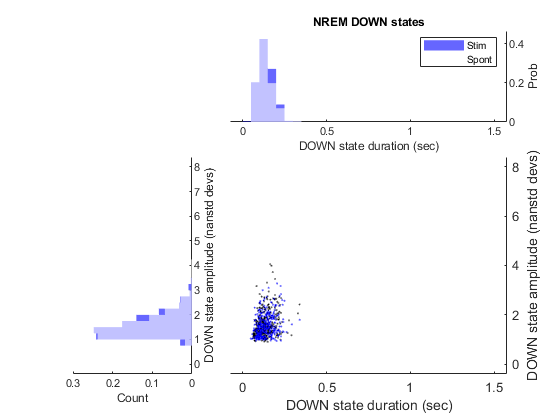

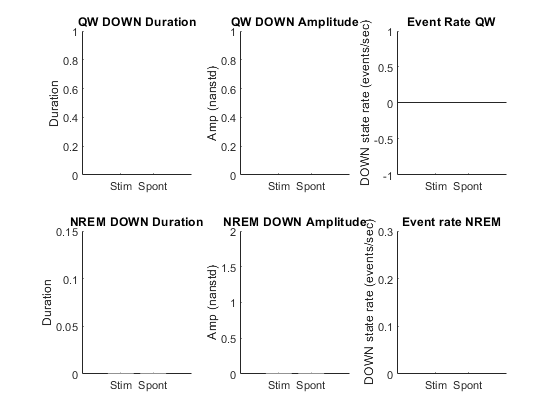

loading spikes from cellinfo file..
loading spikes from cellinfo file..
loading spikes from cellinfo file..
loading spikes from cellinfo file..


DOWNwin = 1×60 logical array
   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


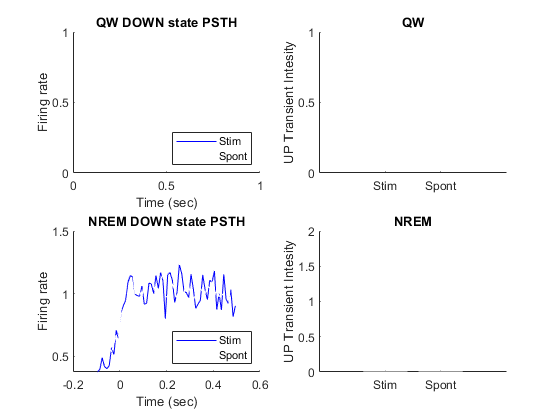

optoInts = getOptoInts(basepath, optostim, facemotionThresh);

Animal6560b.ipsi = analyzeDOWNStates(basepath, SW, spikes, optostim, optoInts);

if checkDOWNDetection
    JR_EventExplorer(basepath, SW, 'spikes', spikesAll, 'lfp', dropLFPChans(lfp, L5Chan))
end

## Animal 6556

Day 2 - Session A

basepath = char(serverPath + '\6556\JR_23_08_22_ChR2_dual_animal_6556_session_A\JR_23_08_22_ChR2_dual_animal_6556_session_A_230822_100542');

spikes = bz_GetSpikes('basepath', basepath,'spikeGroups',1);

loading spikes from cellinfo file..


spikesMU = GetMUA('basepath', basepath,'spikeGroups',1);

loading mua from cellinfo file..


spikesAll = SSTnNOS.concatenateSpikeStructs(spikes, spikesMU);

lfp = bz_GetLFP(0:63, 'basepath',basepath);

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


lfp.data = lfp.data - median(lfp.data,2);

channelDepths = layerLocalization(basepath);

% Choose a channel in L5
[~, L5ChanInd] = min(abs(channelDepths(1,:) - 700));
co = getChannelOrder2('H3');
L5Chan = co(L5ChanInd) - 1;

SW = DetectSlowWaves(basepath, 'lfp', lfp, 'spikes', spikesAll, 'DetectionChannel', L5Chan, 'forceReload', false,...
     'joinwindur',0.005, 'noPrompts',true);

Slow Oscillation already Detected, loading JR_23_08_22_ChR2_dual_animal_6556_session_A_230822_100542.SlowWaves.events.mat



% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(basepath, optoChan_0Ind);

Loading Channels 133 (0-indexing, a la Neuroscope)
loading LFP file...


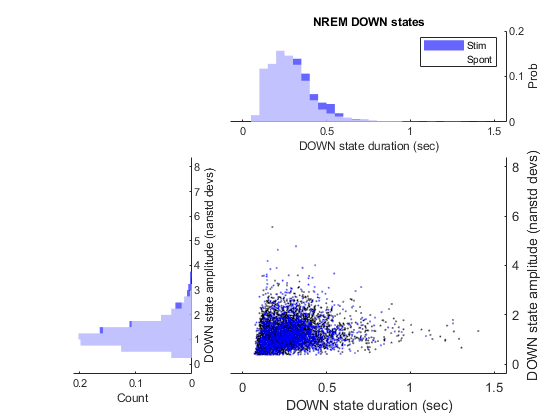

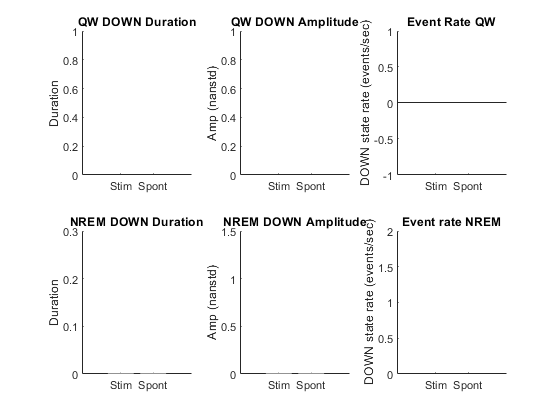

loading spikes from cellinfo file..
loading spikes from cellinfo file..
loading spikes from cellinfo file..
loading spikes from cellinfo file..


DOWNwin = 1×60 logical array
   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


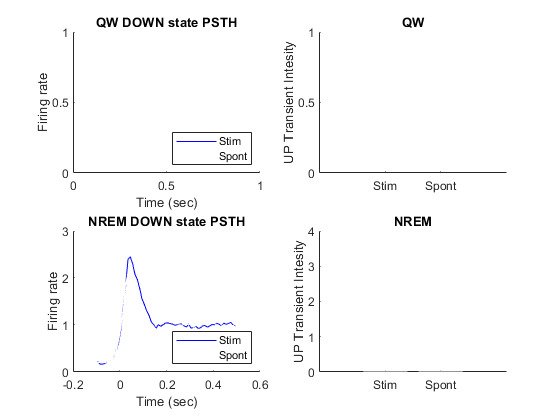

optoInts = getOptoInts(basepath, optostim, facemotionThresh);

Animal6556.ipsi = analyzeDOWNStates(basepath, SW, spikes, optostim, optoInts);


if checkDOWNDetection
    JR_EventExplorer(basepath, SW, 'spikes', spikesAll, 'lfp', dropLFPChans(lfp, L5Chan))
end

Day 2 - Session C

basepath = char(serverPath + '\6556\JR_23_08_23_ChR2_dual_animal_6556_session_C\JR_23_08_23_ChR2_dual_animal_6556_session_C_230823_100827');

spikes = bz_GetSpikes('basepath', basepath,'spikeGroups',1);

loading spikes from cellinfo file..


spikesMU = GetMUA('basepath', basepath,'spikeGroups',1);

loading mua from cellinfo file..


spikesAll = SSTnNOS.concatenateSpikeStructs(spikes, spikesMU);

lfp = bz_GetLFP(0:63, 'basepath',basepath);

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


lfp.data = lfp.data - median(lfp.data,2);

channelDepths = layerLocalization(basepath);

% Choose a channel in L5
[~, L5ChanInd] = min(abs(channelDepths(1,:) - 700));
co = getChannelOrder2('H3');
L5Chan = co(L5ChanInd) - 1;

SW = DetectSlowWaves(basepath, 'lfp', lfp, 'spikes', spikesAll, 'DetectionChannel', L5Chan, 'forceReload', false,...
    'joinwindur',0.005, 'noPrompts',true);

Slow Oscillation already Detected, loading JR_23_08_23_ChR2_dual_animal_6556_session_C_230823_100827.SlowWaves.events.mat



% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(basepath, optoChan_0Ind);

Loading Channels 133 (0-indexing, a la Neuroscope)
loading LFP file...


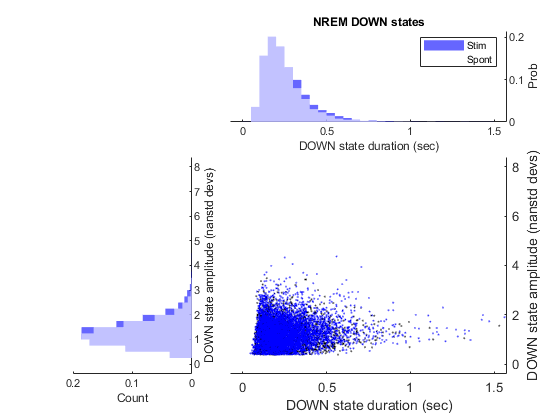

loading spikes from cellinfo file..
loading spikes from cellinfo file..
loading spikes from cellinfo file..
loading spikes from cellinfo file..


DOWNwin = 1×60 logical array
   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


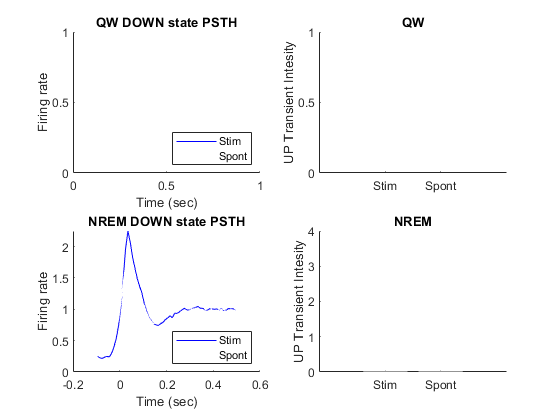

optoInts = getOptoInts(basepath, optostim, facemotionThresh);

Animal6556b.ipsi = analyzeDOWNStates(basepath, SW, spikes, optostim, optoInts);


if checkDOWNDetection
    JR_EventExplorer(basepath, SW, 'spikes', spikesAll, 'lfp', dropLFPChans(lfp, L5Chan))
end

Day 4 - Session A

basepath = char(serverPath + '\6556\JR_23_08_24_ChR2_dual_animal_6556_session_A\JR_23_08_24_ChR2_dual_animal_6556_session_A_230824_105116');

spikes = bz_GetSpikes('basepath', basepath,'spikeGroups',1);

loading spikes from cellinfo file..


spikesMU = GetMUA('basepath', basepath,'spikeGroups',1);

loading mua from cellinfo file..


spikesAll = SSTnNOS.concatenateSpikeStructs(spikes, spikesMU);

lfp = bz_GetLFP(0:63, 'basepath',basepath);

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


lfp.data = lfp.data - median(lfp.data,2);

channelDepths = layerLocalization(basepath);

% Choose a channel in L5
[~, L5ChanInd] = min(abs(channelDepths(1,:) - 700));
co = getChannelOrder2('H3');
L5Chan = co(L5ChanInd) - 1;

SW = DetectSlowWaves(basepath, 'lfp', lfp, 'spikes', spikesAll, 'DetectionChannel', L5Chan, 'forceReload', false,...
    'joinwindur',0.005, 'noPrompts',true);

Slow Oscillation already Detected, loading JR_23_08_24_ChR2_dual_animal_6556_session_A_230824_105116.SlowWaves.events.mat



% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(basepath, optoChan_0Ind);

Loading Channels 133 (0-indexing, a la Neuroscope)
loading LFP file...


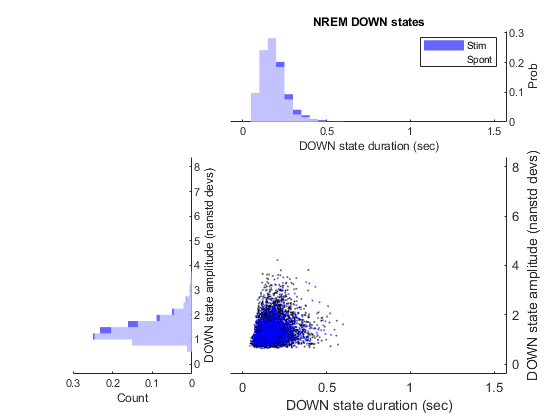

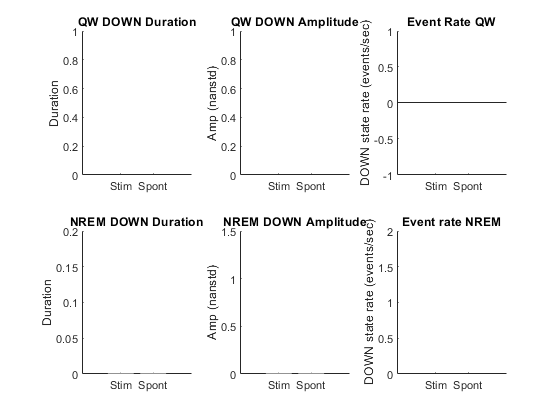

loading spikes from cellinfo file..
loading spikes from cellinfo file..
loading spikes from cellinfo file..
loading spikes from cellinfo file..


DOWNwin = 1×60 logical array
   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


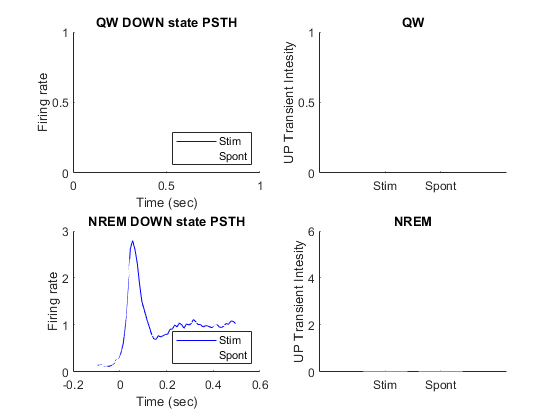

optoInts = getOptoInts(basepath, optostim, facemotionThresh);

Animal6556c.ipsi = analyzeDOWNStates(basepath, SW, spikes, optostim, optoInts);


if checkDOWNDetection
    JR_EventExplorer(basepath, SW, 'spikes', spikesAll, 'lfp', dropLFPChans(lfp, L5Chan))
end

Day 5 - Session C

basepath = char(serverPath + '\6556\JR_23_08_25_ChR2_dual_animal_6556_session_C\JR_23_08_25_ChR2_dual_animal_6556_session_C_230825_104818');

spikes = bz_GetSpikes('basepath', basepath,'spikeGroups',1);

loading spikes from cellinfo file..


spikesMU = GetMUA('basepath', basepath,'spikeGroups',1);

loading mua from cellinfo file..


spikesAll = SSTnNOS.concatenateSpikeStructs(spikes, spikesMU);

lfp = bz_GetLFP(0:63, 'basepath',basepath);

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


lfp.data = lfp.data - median(lfp.data,2);

channelDepths = layerLocalization(basepath);

% Choose a channel in L5
[~, L5ChanInd] = min(abs(channelDepths(1,:) - 700));
co = getChannelOrder2('H3');
L5Chan = co(L5ChanInd) - 1;

SW = DetectSlowWaves(basepath, 'lfp', lfp, 'spikes', spikesAll, 'DetectionChannel', L5Chan, 'forceReload', false,...
    'joinwindur',0.005, 'noPrompts',true);

Slow Oscillation already Detected, loading JR_23_08_25_ChR2_dual_animal_6556_session_C_230825_104818.SlowWaves.events.mat



% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(basepath, optoChan_0Ind);

Loading Channels 133 (0-indexing, a la Neuroscope)
loading LFP file...


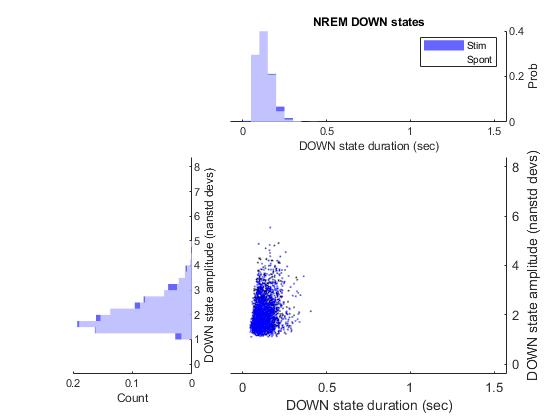

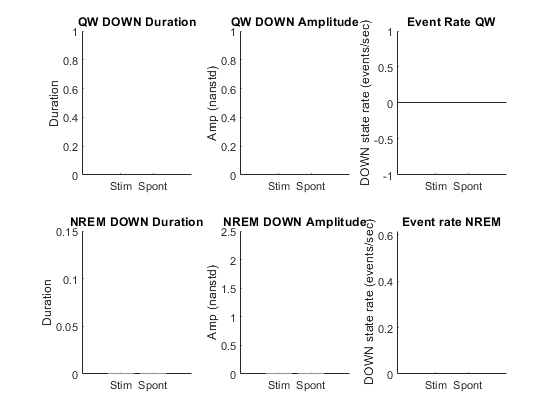

loading spikes from cellinfo file..
loading spikes from cellinfo file..
loading spikes from cellinfo file..
loading spikes from cellinfo file..


DOWNwin = 1×60 logical array
   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


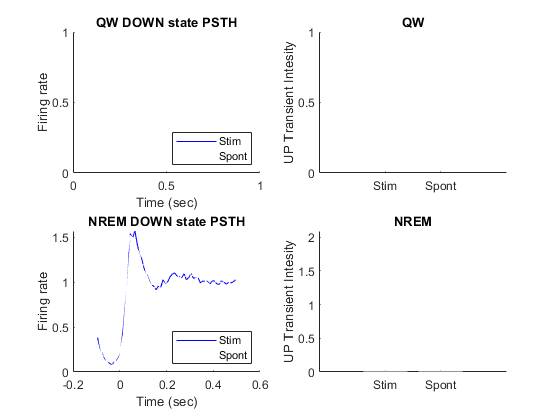

optoInts = getOptoInts(basepath, optostim, facemotionThresh);

Animal6556d.ipsi = analyzeDOWNStates(basepath, SW, spikes, optostim, optoInts);


if checkDOWNDetection
    JR_EventExplorer(basepath, SW, 'spikes', spikesAll, 'lfp', dropLFPChans(lfp, L5Chan))
end

## Animal 7149

Day 2 - Session A

basepath = char(serverPath + '\7149\JR_23_09_06_ChR2_dual_animal_7149_session_A\JR_23_09_06_ChR2_dual_animal_7149_session_A_230906_103733');

spikes = bz_GetSpikes('basepath', basepath,'spikeGroups',1);

loading spikes from cellinfo file..


% spikesMU = GetMUA('basepath', basepath,'spikeGroups',1);
% spikesAll = SSTnNOS.concatenateSpikeStructs(spikes, spikesMU);

lfp = bz_GetLFP(0:63, 'basepath',basepath);

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


lfp.data = lfp.data - median(lfp.data,2);

channelDepths = layerLocalization(basepath);

% Choose a channel in L5
[~, L5ChanInd] = min(abs(channelDepths(1,:) - 700));
co = getChannelOrder2('H3')

co =     38    40    42    45    43    49    34    36    48    35    33    44    46    41    39    37    63    61    60    58    56    54    52    50    47    51    53    55    57    59    62    64     1     3     6     8    10    12    14    16    17    13    11     9     7     5     4     2    28    26


L5Chan = co(L5ChanInd) - 1;
% L5Chan = 45

SW = DetectSlowWaves(basepath, 'lfp', lfp, 'spikes', spikes, 'DetectionChannel', L5Chan, 'forceReload', false,...
    'joinwindur',0.005, 'noPrompts',true);

Slow Oscillation already Detected, loading JR_23_09_06_ChR2_dual_animal_7149_session_A_230906_103733.SlowWaves.events.mat



% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(basepath, optoChan_0Ind);

Loading Channels 133 (0-indexing, a la Neuroscope)
loading LFP file...


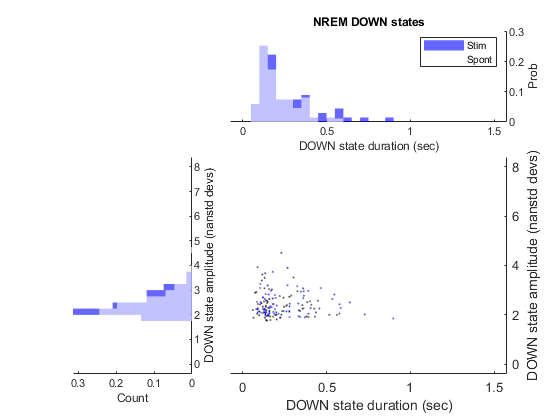

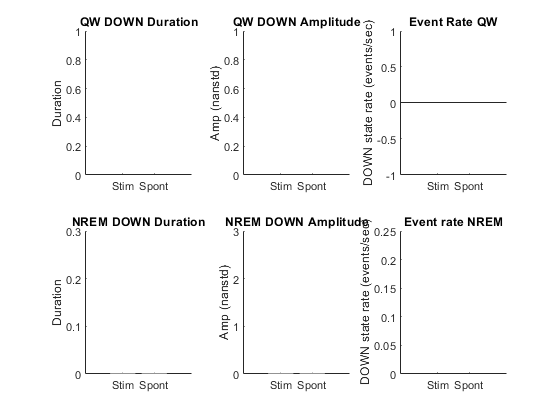

loading spikes from cellinfo file..
loading spikes from cellinfo file..
loading spikes from cellinfo file..
loading spikes from cellinfo file..


DOWNwin = 1×60 logical array
   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


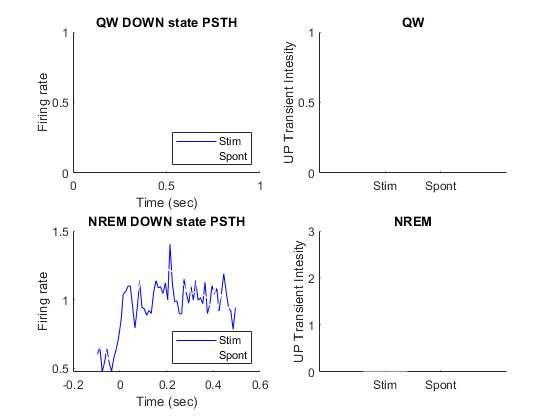

optoInts = getOptoInts(basepath, optostim, facemotionThresh);

Animal7149.ipsi = analyzeDOWNStates(basepath, SW, spikes, optostim, optoInts);


if checkDOWNDetection
    JR_EventExplorer(basepath, SW, 'spikes', spikesAll, 'lfp', dropLFPChans(lfp, L5Chan))
end

Day 3 - Session C

Detection of slow waves yields positive deflections with more spikes...

% basepath = 'W:\Jacob Ratliff\JR_Ephys_Data\ChR2_dual_summer_2023\7149\JR_23_09_07_ChR2_dual_animal_7149_session_C\JR_23_09_07_ChR2_dual_animal_7149_session_C_230907_100125';
% 
% spikes = bz_GetSpikes('basepath', basepath,'spikeGroups',1);
% % spikesMU = GetMUA('basepath', basepath,'spikeGroups',1);
% % spikesAll = SSTnNOS.concatenateSpikeStructs(spikes, spikesMU);
% 
% lfp = bz_GetLFP(0:63, 'basepath',basepath);
% lfp.data = lfp.data - median(lfp.data,2);
% 
% channelDepths = layerLocalization(basepath);
% 
% % Choose a channel in L5
% [~, L5ChanInd] = min(abs(channelDepths(1,:) - 700));
% co = getChannelOrder2('H3');
% L5Chan = co(L5ChanInd) - 1;
% 
% SW = DetectSlowWaves(basepath, 'lfp', lfp, 'spikes', spikes, 'DetectionChannel', L5Chan, 'forceReload', false,...
%     'joinwindur',0.005, 'noPrompts',true);
% 
% % Get details of optogenetic stimulation
% optostim = SSTnNOS.getOptoTrialInfo(basepath, optoChan_0Ind);
% optoInts = getOptoInts(basepath, optostim, facemotionThresh);
% 
% Animal7149b.ipsi = analyzeDOWNStates(basepath, SW, spikes, optostim, optoInts);
% 
% if checkDOWNDetection
%     JR_EventExplorer(basepath, SW, 'spikes', spikes, 'lfp', dropLFPChans(lfp, L5Chan))
% end

## Animal 7158

Day 2 - Session A

basepath = char(serverPath + '\7158\JR_23_09_13_ChR2_dual_animal_7158_session_A\JR_23_09_13_ChR2_dual_animal_7158_session_A_230913_101804');

spikes = bz_GetSpikes('basepath', basepath,'spikeGroups',1);

loading spikes from cellinfo file..


spikesMU = GetMUA('basepath', basepath,'spikeGroups',1);

loading mua from cellinfo file..


spikesAll = SSTnNOS.concatenateSpikeStructs(spikes, spikesMU);

lfp = bz_GetLFP(0:63, 'basepath',basepath);

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


lfp.data = lfp.data - median(lfp.data,2);

channelDepths = layerLocalization(basepath);

% Choose a channel in L5
[~, L5ChanInd] = min(abs(channelDepths(1,:) - 700));
co = getChannelOrder2('H3')

co =     38    40    42    45    43    49    34    36    48    35    33    44    46    41    39    37    63    61    60    58    56    54    52    50    47    51    53    55    57    59    62    64     1     3     6     8    10    12    14    16    17    13    11     9     7     5     4     2    28    26


L5Chan = co(L5ChanInd) - 1;

SW = DetectSlowWaves(basepath, 'lfp', lfp, 'spikes', spikesAll, 'DetectionChannel', L5Chan, 'forceReload', false,...
    'joinwindur',0.005, 'noPrompts',true);

Slow Oscillation already Detected, loading JR_23_09_13_ChR2_dual_animal_7158_session_A_230913_101804.SlowWaves.events.mat



% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(basepath, optoChan_0Ind);

Loading Channels 133 (0-indexing, a la Neuroscope)
loading LFP file...


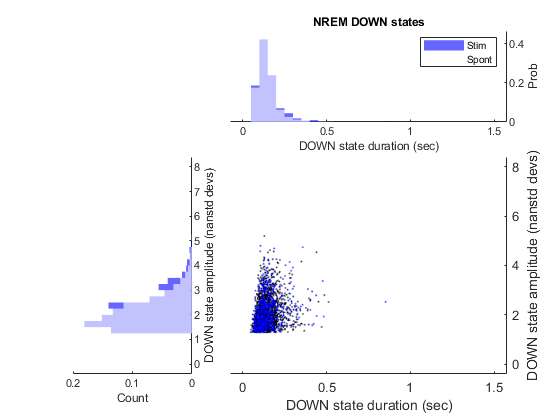

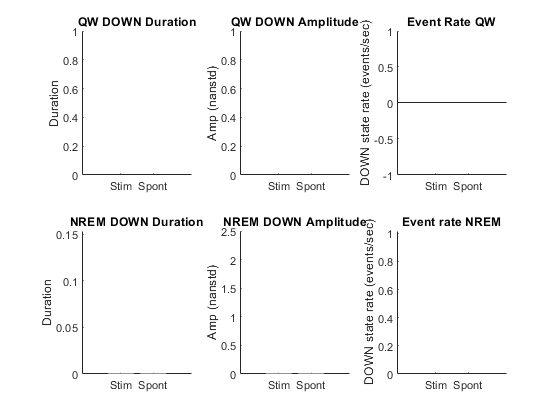

loading spikes from cellinfo file..
loading spikes from cellinfo file..
loading spikes from cellinfo file..
loading spikes from cellinfo file..


DOWNwin = 1×60 logical array
   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


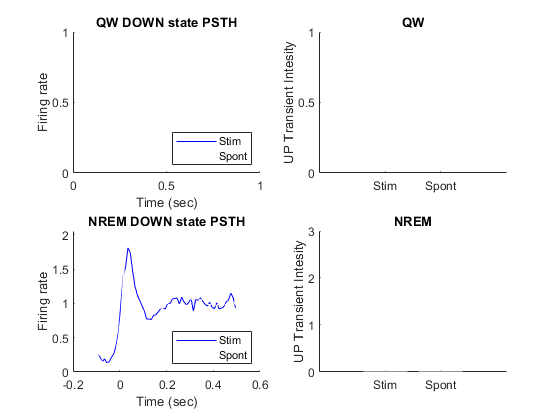

optoInts = getOptoInts(basepath, optostim, facemotionThresh);

Animal7158.ipsi = analyzeDOWNStates(basepath, SW, spikes, optostim, optoInts);


if checkDOWNDetection
    JR_EventExplorer(basepath, SW, 'spikes', spikesAll, 'lfp', dropLFPChans(lfp, L5Chan))
end

Day 3 - Session C

basepath = char(serverPath + '\7158\JR_23_09_12_ChR2_dual_animal_7158_session_C\JR_23_09_12_ChR2_dual_animal_7158_session_C_230912_094221');

spikes = bz_GetSpikes('basepath', basepath,'spikeGroups',1);

loading spikes from cellinfo file..


% spikesMU = GetMUA('basepath', basepath,'spikeGroups',1);
% spikesAll = SSTnNOS.concatenateSpikeStructs(spikes, spikesMU);

lfp = bz_GetLFP(0:63, 'basepath',basepath);

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


lfp.data = lfp.data - median(lfp.data,2);

channelDepths = layerLocalization(basepath);

% Choose a channel in L5
[~, L5ChanInd] = min(abs(channelDepths(1,:) - 700));
co = getChannelOrder2('H3')

co =     38    40    42    45    43    49    34    36    48    35    33    44    46    41    39    37    63    61    60    58    56    54    52    50    47    51    53    55    57    59    62    64     1     3     6     8    10    12    14    16    17    13    11     9     7     5     4     2    28    26


L5Chan = co(L5ChanInd) - 1;

SW = DetectSlowWaves(basepath, 'lfp', lfp, 'spikes', spikes, 'DetectionChannel', L5Chan, 'forceReload', false,...
    'joinwindur',0.005, 'noPrompts',true);

Slow Oscillation already Detected, loading JR_23_09_12_ChR2_dual_animal_7158_session_C_230912_094221.SlowWaves.events.mat



% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(basepath, optoChan_0Ind);

Loading Channels 133 (0-indexing, a la Neuroscope)
loading LFP file...


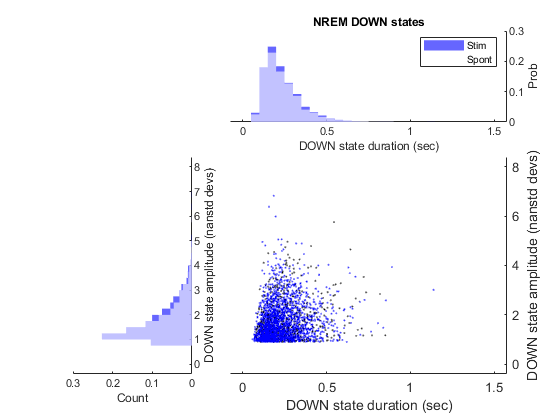

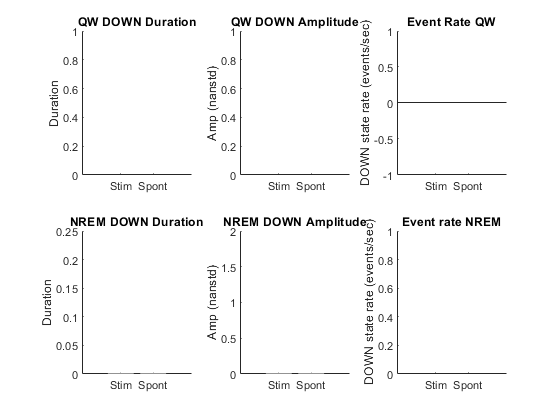

loading spikes from cellinfo file..
loading spikes from cellinfo file..
loading spikes from cellinfo file..
loading spikes from cellinfo file..


DOWNwin = 1×60 logical array
   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


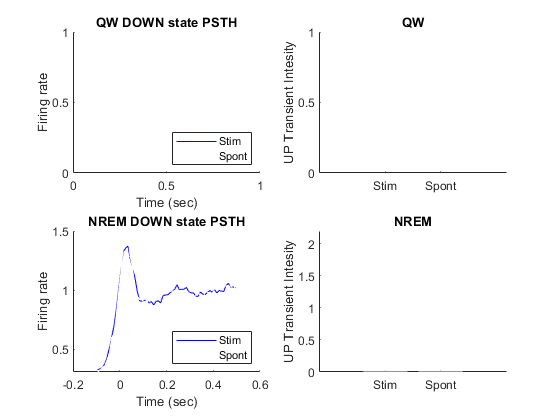

optoInts = getOptoInts(basepath, optostim, facemotionThresh);

Animal7158b.ipsi = analyzeDOWNStates(basepath, SW, spikes, optostim, optoInts);


if checkDOWNDetection
    JR_EventExplorer(basepath, SW, 'spikes', spikes, 'lfp', dropLFPChans(lfp, L5Chan))
end

Day 4 - Session A

basepath = char(serverPath + '\7158\JR_23_09_13_ChR2_dual_animal_7158_session_A\JR_23_09_13_ChR2_dual_animal_7158_session_A_230913_101804');

spikes = bz_GetSpikes('basepath', basepath,'spikeGroups',1);

loading spikes from cellinfo file..


spikesMU = GetMUA('basepath', basepath,'spikeGroups',1);

loading mua from cellinfo file..


spikesAll = SSTnNOS.concatenateSpikeStructs(spikes, spikesMU);

lfp = bz_GetLFP(0:63, 'basepath',basepath);

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


lfp.data = lfp.data - median(lfp.data,2);

channelDepths = layerLocalization(basepath);

% Choose a channel in L5
[~, L5ChanInd] = min(abs(channelDepths(1,:) - 700));
co = getChannelOrder2('H3')

co =     38    40    42    45    43    49    34    36    48    35    33    44    46    41    39    37    63    61    60    58    56    54    52    50    47    51    53    55    57    59    62    64     1     3     6     8    10    12    14    16    17    13    11     9     7     5     4     2    28    26


L5Chan = co(L5ChanInd) - 1;

SW = DetectSlowWaves(basepath, 'lfp', lfp, 'spikes', spikesAll, 'DetectionChannel', L5Chan, 'forceReload', false,...
    'joinwindur',0.005, 'noPrompts',true);

Slow Oscillation already Detected, loading JR_23_09_13_ChR2_dual_animal_7158_session_A_230913_101804.SlowWaves.events.mat



% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(basepath, optoChan_0Ind);

Loading Channels 133 (0-indexing, a la Neuroscope)
loading LFP file...


loading spikes from cellinfo file..
loading spikes from cellinfo file..
loading spikes from cellinfo file..
loading spikes from cellinfo file..


DOWNwin = 1×60 logical array
   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


optoInts = getOptoInts(basepath, optostim, facemotionThresh);

Animal7158c.ipsi = analyzeDOWNStates(basepath, SW, spikes, optostim, optoInts);


if checkDOWNDetection
    JR_EventExplorer(basepath, SW, 'spikes', spikesAll, 'lfp', dropLFPChans(lfp, L5Chan))
end

## New data for revision

data_loc = "G:\revision_opto_sessions";
optoChan_0Ind = 69;
facemotionThresh = 1000;

## Animal 6575

Day 1 - Session A - 04/15/24

basepath = char(data_loc + '\6575\JR_24_04_15_SSTnNOS_ChR2_6575_session_A\JR_24_04_15_SSTnNOS_ChR2_6575_session_A_240415_105602');


spikes = bz_GetSpikes('basepath', basepath,'spikeGroups',1,'region','CTX');

loading spikes from cellinfo file..


% spikesMU = GetMUA('basepath', basepath,'spikeGroups',1);
% spikesAll = SSTnNOS.concatenateSpikeStructs(spikes, spikesMU);

lfp = bz_GetLFP(0:63, 'basepath',basepath);

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


lfp.data = lfp.data - median(lfp.data,2);

channelDepths = layerLocalization(basepath);

% Choose a channel in L5
[~, L5ChanInd] = min(abs(channelDepths(1,:) - 700));
co = getChannelOrder2('H3')

co =     38    40    42    45    43    49    34    36    48    35    33    44    46    41    39    37    63    61    60    58    56    54    52    50    47    51    53    55    57    59    62    64     1     3     6     8    10    12    14    16    17    13    11     9     7     5     4     2    28    26


L5Chan = co(L5ChanInd) - 1;

SW = DetectSlowWaves(basepath, 'lfp', lfp, 'spikes', spikes, 'DetectionChannel', L5Chan, 'forceReload', false,...
    'joinwindur',0.005, 'noPrompts',true);

Slow Oscillation already Detected, loading JR_24_04_15_SSTnNOS_ChR2_6575_session_A_240415_105602.SlowWaves.events.mat


  
% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(basepath, optoChan_0Ind);

Loading Channels 69 (0-indexing, a la Neuroscope)
loading LFP file...


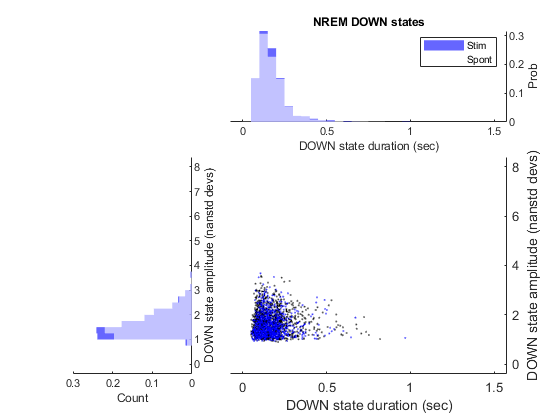

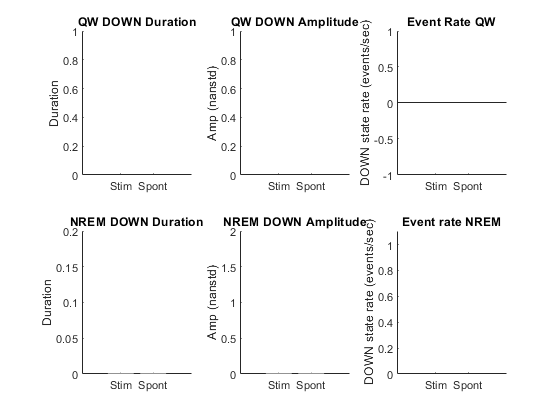

loading spikes from cellinfo file..
loading spikes from cellinfo file..
loading spikes from cellinfo file..
loading spikes from cellinfo file..


DOWNwin = 1×60 logical array
   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


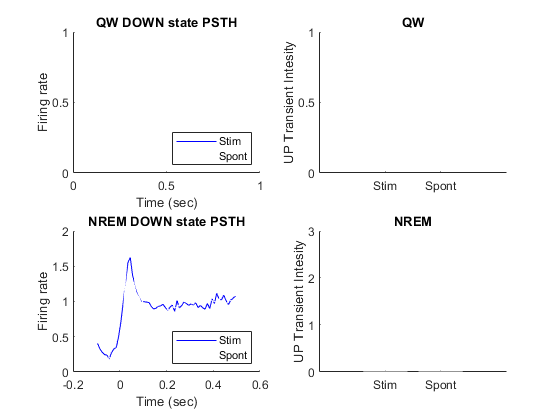

optoInts = getOptoInts(basepath, optostim, facemotionThresh);

Animal6575a.ipsi = analyzeDOWNStates(basepath, SW, spikes, optostim, optoInts);


if checkDOWNDetection
    JR_EventExplorer(basepath, SW, 'spikes', spikes, 'lfp', dropLFPChans(lfp, L5Chan))
end

Day 5 - Session A - 04/19/24

basepath = char(data_loc + '\6575\JR_24_04_19_SSTnNOS_ChR2_6575_session_A\JR_24_04_19_SSTnNOS_ChR2_6575_session_A_240419_085822');

spikes = bz_GetSpikes('basepath', basepath,'spikeGroups',1,'region','CTX');

loading spikes from cellinfo file..


% spikesMU = GetMUA('basepath', basepath,'spikeGroups',1);
% spikesAll = SSTnNOS.concatenateSpikeStructs(spikes, spikesMU);

lfp = bz_GetLFP(0:63, 'basepath',basepath);

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


lfp.data = lfp.data - median(lfp.data,2);

channelDepths = layerLocalization(basepath);

% Choose a channel in L5
[~, L5ChanInd] = min(abs(channelDepths(1,:) - 700));
co = getChannelOrder2('H3')

co =     38    40    42    45    43    49    34    36    48    35    33    44    46    41    39    37    63    61    60    58    56    54    52    50    47    51    53    55    57    59    62    64     1     3     6     8    10    12    14    16    17    13    11     9     7     5     4     2    28    26


L5Chan = co(L5ChanInd) - 1;

SW = DetectSlowWaves(basepath, 'lfp', lfp, 'spikes', spikes, 'DetectionChannel', L5Chan, 'forceReload', false,...
    'joinwindur',0.005, 'noPrompts',true);

Slow Oscillation already Detected, loading JR_24_04_19_SSTnNOS_ChR2_6575_session_A_240419_085822.SlowWaves.events.mat



% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(basepath, optoChan_0Ind);

Loading Channels 69 (0-indexing, a la Neuroscope)
loading LFP file...


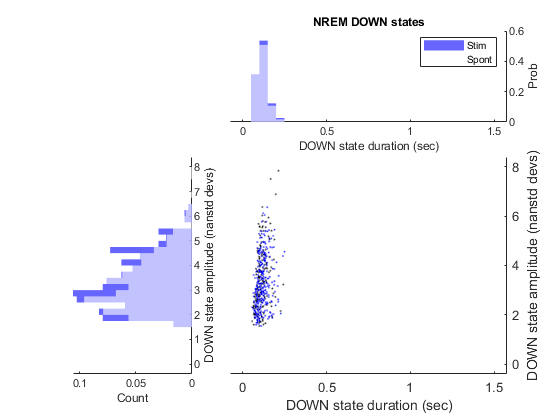

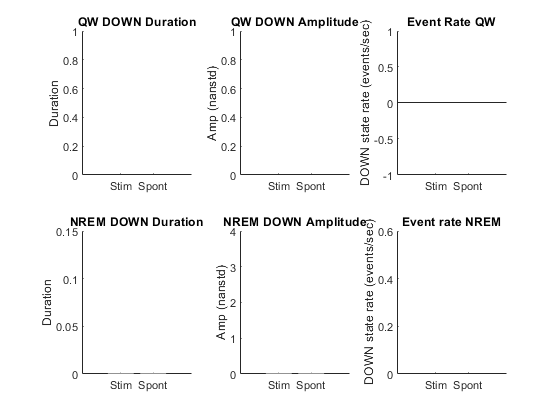

loading spikes from cellinfo file..
loading spikes from cellinfo file..
loading spikes from cellinfo file..
loading spikes from cellinfo file..


DOWNwin = 1×60 logical array
   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


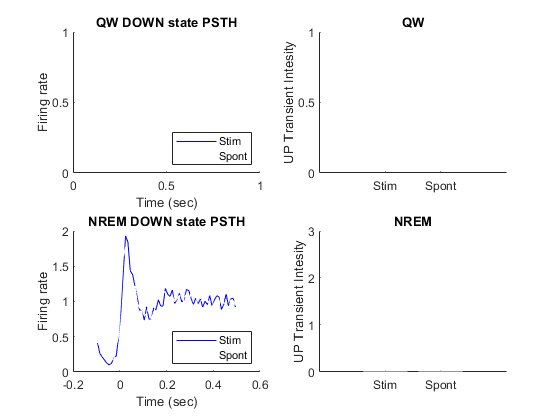

optoInts = getOptoInts(basepath, optostim, facemotionThresh);

Animal6575b.ipsi = analyzeDOWNStates(basepath, SW, spikes, optostim, optoInts);


if checkDOWNDetection
    JR_EventExplorer(basepath, SW, 'spikes', spikes, 'lfp', dropLFPChans(lfp, L5Chan))
end

## Animal 6576

Day 2 - Session A - 04/16/24

Detection not so great

basepath = char(data_loc + '\6576\JR_24_04_16_SSTnNOS_ChR2_6576_session_A\JR_24_04_16_SSTnNOS_ChR2_6576_session_A_240416_103011');

spikes = bz_GetSpikes('basepath', basepath,'spikeGroups',1,'region','CTX');

loading spikes from cellinfo file..


% spikesMU = GetMUA('basepath', basepath,'spikeGroups',1);
% spikesAll = SSTnNOS.concatenateSpikeStructs(spikes, spikesMU);

lfp = bz_GetLFP(0:63, 'basepath',basepath);

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


lfp.data = lfp.data - median(lfp.data,2);

channelDepths = layerLocalization(basepath);

% Choose a channel in L5
% [~, L5ChanInd] = min(abs(channelDepths(1,:) - 700));
% co = getChannelOrder2('H3')
% L5Chan = co(L5ChanInd) - 1;
overrideChan = 0;

SW = DetectSlowWaves(basepath, 'lfp', lfp, 'spikes', spikes, 'DetectionChannel', overrideChan, 'forceReload', false,...
    'joinwindur',0.005, 'noPrompts',true);

Slow Oscillation already Detected, loading JR_24_04_16_SSTnNOS_ChR2_6576_session_A_240416_103011.SlowWaves.events.mat


  
% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(basepath, optoChan_0Ind);

Loading Channels 69 (0-indexing, a la Neuroscope)
loading LFP file...


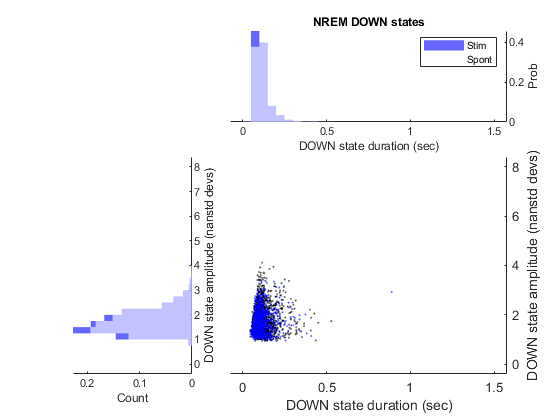

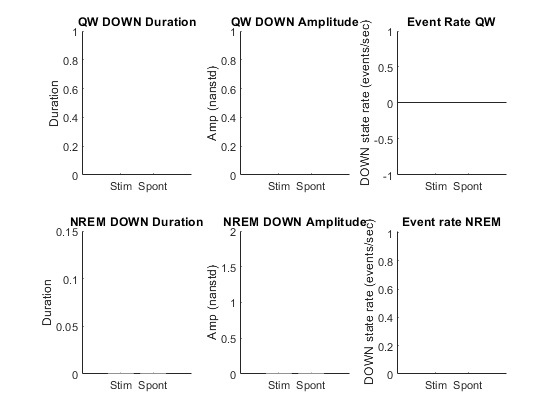

loading spikes from cellinfo file..
loading spikes from cellinfo file..
loading spikes from cellinfo file..
loading spikes from cellinfo file..


DOWNwin = 1×60 logical array
   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


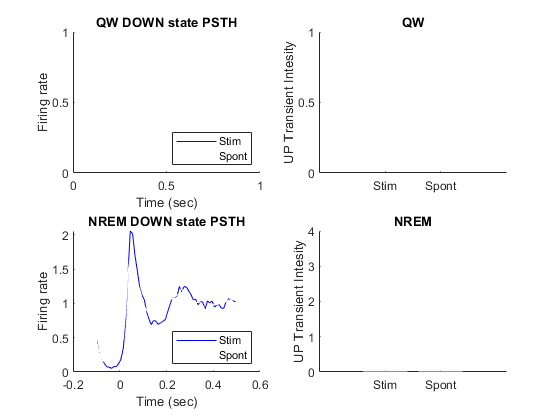

optoInts = getOptoInts(basepath, optostim, facemotionThresh);

Animal6576.ipsi = analyzeDOWNStates(basepath, SW, spikes, optostim, optoInts);


if checkDOWNDetection
    JR_EventExplorer(basepath, SW, 'spikes', spikes, 'lfp', dropLFPChans(lfp, overrideChan))
end

## Animal 6692

Day 5 - Session A - 03/29/24

basepath = char(data_loc + '\6692\JR_24_03_29_SSTnNOS_ChR2_6692_session_A\JR_24_03_29_SSTnNOS_ChR2_6692_session_A_240329_085446');

spikes = bz_GetSpikes('basepath', basepath,'spikeGroups',1,'region','CTX');

loading spikes from cellinfo file..


% spikesMU = GetMUA('basepath', basepath,'spikeGroups',1);
% spikesAll = SSTnNOS.concatenateSpikeStructs(spikes, spikesMU);

lfp = bz_GetLFP(0:63, 'basepath',basepath);

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


lfp.data = lfp.data - median(lfp.data,2);

channelDepths = layerLocalization(basepath);

% Choose a channel in L5
[~, L5ChanInd] = min(abs(channelDepths(1,:) - 700));
co = getChannelOrder2('H3')

co =     38    40    42    45    43    49    34    36    48    35    33    44    46    41    39    37    63    61    60    58    56    54    52    50    47    51    53    55    57    59    62    64     1     3     6     8    10    12    14    16    17    13    11     9     7     5     4     2    28    26


L5Chan = co(L5ChanInd) - 1;

SW = DetectSlowWaves(basepath, 'lfp', lfp, 'spikes', spikes, 'DetectionChannel', L5Chan, 'forceReload', false,...
    'joinwindur',0.005, 'noPrompts',true);

Slow Oscillation already Detected, loading JR_24_03_29_SSTnNOS_ChR2_6692_session_A_240329_085446.SlowWaves.events.mat


  
% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(basepath, optoChan_0Ind);

Loading Channels 69 (0-indexing, a la Neuroscope)
loading LFP file...


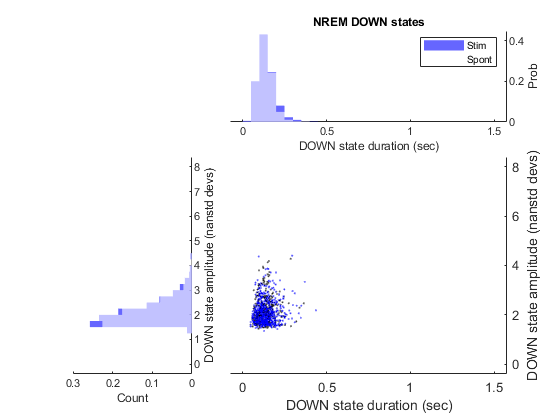

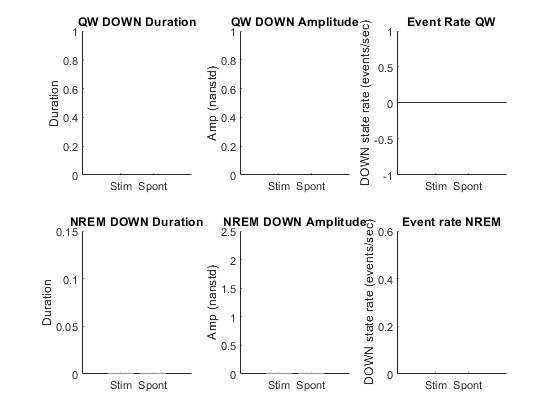

loading spikes from cellinfo file..
loading spikes from cellinfo file..
loading spikes from cellinfo file..
loading spikes from cellinfo file..


DOWNwin = 1×60 logical array
   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


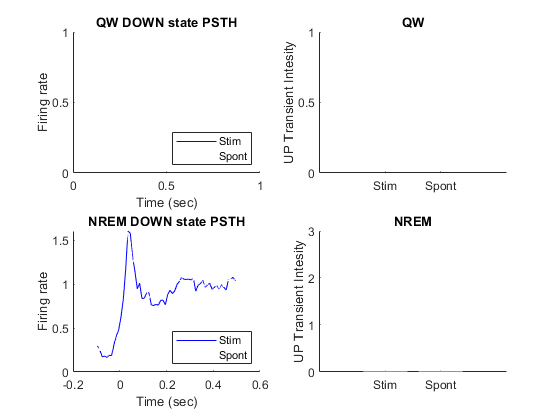

optoInts = getOptoInts(basepath, optostim, facemotionThresh);

Animal6692.ipsi = analyzeDOWNStates(basepath, SW, spikes, optostim, optoInts);


if checkDOWNDetection
    JR_EventExplorer(basepath, SW, 'spikes', spikes, 'lfp', dropLFPChans(lfp, L5Chan))
end

Day 3 (second craniotomy) - Session A - 04/03/24

% basepath = data_loc + '\6692\JR_24_04_03_SSTnNOS_ChR2_6692_right_session_A\JR_24_04_03_SSTnNOS_ChR2_6692_right_session_A_240403_100421';

## Animal 6695

Day 4 - Session A - 03/29/24

% basepath = data_loc + '\6695\JR_24_03_29_SSTnNOS_ChR2_6695_session_A\JR_24_03_29_SSTnNOS_ChR2_6695_session_A_240329_123702';

Day 3 (second crainotomy) - Session A - 04/03/24

basepath = char(data_loc + '\6695\JR_24_04_03_SSTnNOS_ChR2_6695_right_session_A\JR_24_04_03_SSTnNOS_ChR2_6695_right_session_A_240403_140338');

spikes = bz_GetSpikes('basepath', basepath,'spikeGroups',1,'region','CTX');

loading spikes from cellinfo file..


% spikesMU = GetMUA('basepath', basepath,'spikeGroups',1);
% spikesAll = SSTnNOS.concatenateSpikeStructs(spikes, spikesMU);

lfp = bz_GetLFP(0:63, 'basepath',basepath);

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


lfp.data = lfp.data - median(lfp.data,2);

channelDepths = layerLocalization(basepath);

% Choose a channel in L5
% [~, L5ChanInd] = min(abs(channelDepths(1,:) - 700));
% co = getChannelOrder2('H3')
% L5Chan = co(L5ChanInd) - 1;
overrideChan = 35;

SW = DetectSlowWaves(basepath, 'lfp', lfp, 'spikes', spikes, 'DetectionChannel', 35, 'forceReload', false,...
    'joinwindur',0.005, 'noPrompts',true);

Slow Oscillation already Detected, loading JR_24_04_03_SSTnNOS_ChR2_6695_right_session_A_240403_140338.SlowWaves.events.mat


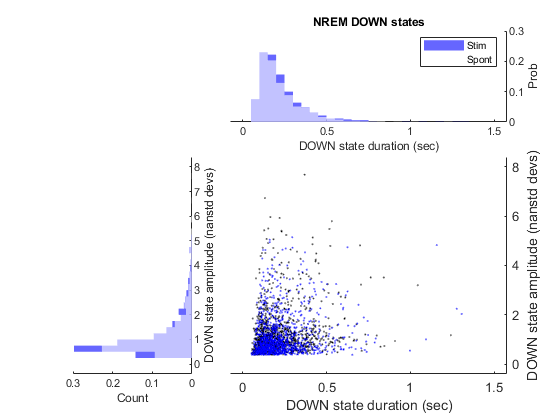

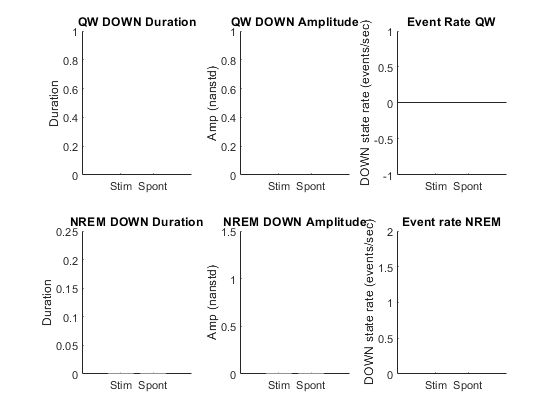

loading spikes from cellinfo file..
loading spikes from cellinfo file..
loading spikes from cellinfo file..
loading spikes from cellinfo file..


DOWNwin = 1×60 logical array
   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


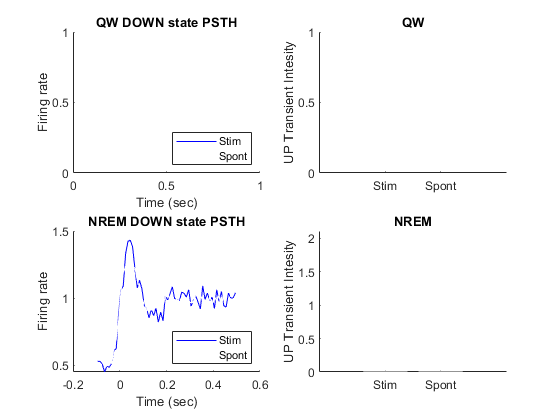

  
% Get details of optogenetic stimulation
% optostim = SSTnNOS.getOptoTrialInfo(basepath, optoChan_0Ind);
load(basepath + "\" + bz_BasenameFromBasepath(basepath) + ".optostim.mat")
optoInts = getOptoInts(basepath, optostim, facemotionThresh);

Animal6695.ipsi = analyzeDOWNStates(basepath, SW, spikes, optostim, optoInts);


if checkDOWNDetection
    JR_EventExplorer(basepath, SW, 'spikes', spikes, 'lfp', dropLFPChans(lfp, L5Chan))
end

## Animal 6750

Day 2 - Session A - 04/16/24

% basepath = char(data_loc + '\6750\JR_24_04_16_SSTnNOS_ChR2_6750_session_A\JR_24_04_16_SSTnNOS_ChR2_6750_session_A_240416_145805');
% 
% spikes = bz_GetSpikes('basepath', basepath,'spikeGroups',1,'region','CTX');
% % spikesMU = GetMUA('basepath', basepath,'spikeGroups',1);
% % spikesAll = SSTnNOS.concatenateSpikeStructs(spikes, spikesMU);
% 
% lfp = bz_GetLFP(0:63, 'basepath',basepath);
% lfp.data = lfp.data - median(lfp.data,2);
% 
% channelDepths = layerLocalization(basepath);
% 
% % Choose a channel in L5
% [~, L5ChanInd] = min(abs(channelDepths(1,:) - 700));
% co = getChannelOrder2('H3')
% L5Chan = co(L5ChanInd) - 1;
% 
% SW = DetectSlowWaves(basepath, 'lfp', lfp, 'spikes', spikes, 'DetectionChannel', L5Chan, 'forceReload', false,...
%     'joinwindur',0.005, 'noPrompts',true);
% 
% % Get details of optogenetic stimulation
% optostim = SSTnNOS.getOptoTrialInfo(basepath, optoChan_0Ind);
% optoInts = getOptoInts(basepath, optostim, facemotionThresh);
% 
% Animal6750.ipsi = analyzeDOWNStates(basepath, SW, spikes, optostim, optoInts);
% 
% if checkDOWNDetection
%     JR_EventExplorer(basepath, SW, 'spikes', spikes, 'lfp', dropLFPChans(lfp, L5Chan))
% end

## Animal 6759

Day 1 - Session A - 04/15/24

Poor detection alongside few spikes and low amp LFP

% basepath = char(data_loc + '\6759\JR_24_04_15_SSTnNOS_ChR2_6759_session_A\JR_24_04_15_SSTnNOS_ChR2_6759_session_A_240415_145147');
% 
% spikes = bz_GetSpikes('basepath', basepath,'spikeGroups',1,'region','CTX');
% % spikesMU = GetMUA('basepath', basepath,'spikeGroups',1);
% % spikesAll = SSTnNOS.concatenateSpikeStructs(spikes, spikesMU);
% 
% lfp = bz_GetLFP(0:63, 'basepath',basepath);
% lfp.data = lfp.data - median(lfp.data,2);
% 
% channelDepths = layerLocalization(basepath);
% 
% % Choose a channel in L5
% [~, L5ChanInd] = min(abs(channelDepths(1,:) - 700));
% co = getChannelOrder2('H3')
% L5Chan = co(L5ChanInd) - 1;
% 
% SW = DetectSlowWaves(basepath, 'lfp', lfp, 'spikes', spikes, 'DetectionChannel', L5Chan, 'forceReload', false,...
%     'joinwindur',0.005, 'noPrompts',true);
% 
% % Get details of optogenetic stimulation
% optostim = SSTnNOS.getOptoTrialInfo(basepath, optoChan_0Ind);
% optoInts = getOptoInts(basepath, optostim, facemotionThresh);
% 
% Animal6759a.ipsi = analyzeDOWNStates(basepath, SW, spikes, optostim, optoInts);
% 
% if checkDOWNDetection
%     JR_EventExplorer(basepath, SW, 'spikes', spikes, 'lfp', dropLFPChans(lfp, L5Chan))
% end

Day 5 - Session A - 04/19/24

basepath = char(data_loc + '\6759\JR_24_04_19_SSTnNOS_ChR2_6759_session_A\JR_24_04_19_SSTnNOS_ChR2_6759_session_A_240419_131907');

spikes = bz_GetSpikes('basepath', basepath,'spikeGroups',1,'region','CTX');

loading spikes from cellinfo file..


% spikesMU = GetMUA('basepath', basepath,'spikeGroups',1);
% spikesAll = SSTnNOS.concatenateSpikeStructs(spikes, spikesMU);

lfp = bz_GetLFP(0:63, 'basepath',basepath);

Loading Channels 0   1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31  32  33  34  35  36  37  38  39  40  41  42  43  44  45  46  47  48  49  50  51  52  53  54  55  56  57  58  59  60  61  62  63 (0-indexing, a la Neuroscope)
loading LFP file...


lfp.data = lfp.data - median(lfp.data,2);

channelDepths = layerLocalization(basepath);

% Choose a channel in L5
% [~, L5ChanInd] = min(abs(channelDepths(1,:) - 700));
% co = getChannelOrder2('H3')
% L5Chan = co(L5ChanInd) - 1;
overrideChan = 12;

SW = DetectSlowWaves(basepath, 'lfp', lfp, 'spikes', spikes, 'DetectionChannel', overrideChan, 'forceReload', false,...
    'joinwindur',0.005, 'noPrompts',true);

Slow Oscillation already Detected, loading JR_24_04_19_SSTnNOS_ChR2_6759_session_A_240419_131907.SlowWaves.events.mat


  
% Get details of optogenetic stimulation
optostim = SSTnNOS.getOptoTrialInfo(basepath, optoChan_0Ind);

Loading Channels 69 (0-indexing, a la Neuroscope)
loading LFP file...


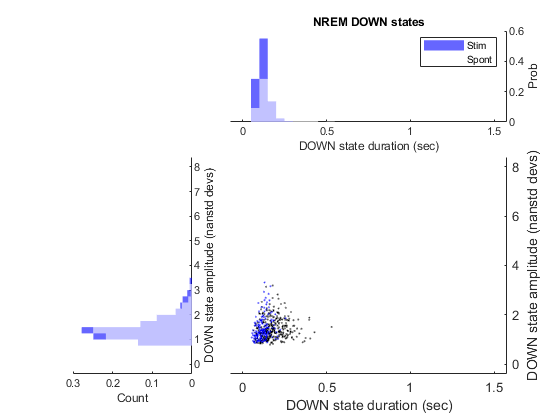

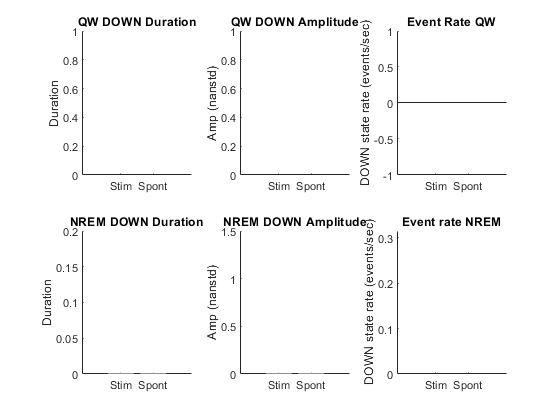

loading spikes from cellinfo file..
loading spikes from cellinfo file..
loading spikes from cellinfo file..
loading spikes from cellinfo file..


DOWNwin = 1×60 logical array
   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


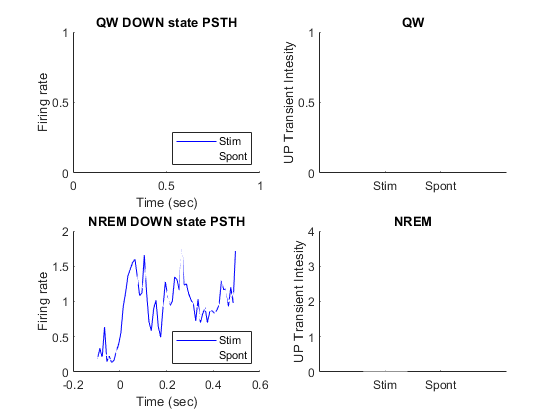

optoInts = getOptoInts(basepath, optostim, facemotionThresh);

Animal6759b.ipsi = analyzeDOWNStates(basepath, SW, spikes, optostim, optoInts);


if checkDOWNDetection
    JR_EventExplorer(basepath, SW, 'spikes', spikes, 'lfp', dropLFPChans(lfp, L5Chan))
end

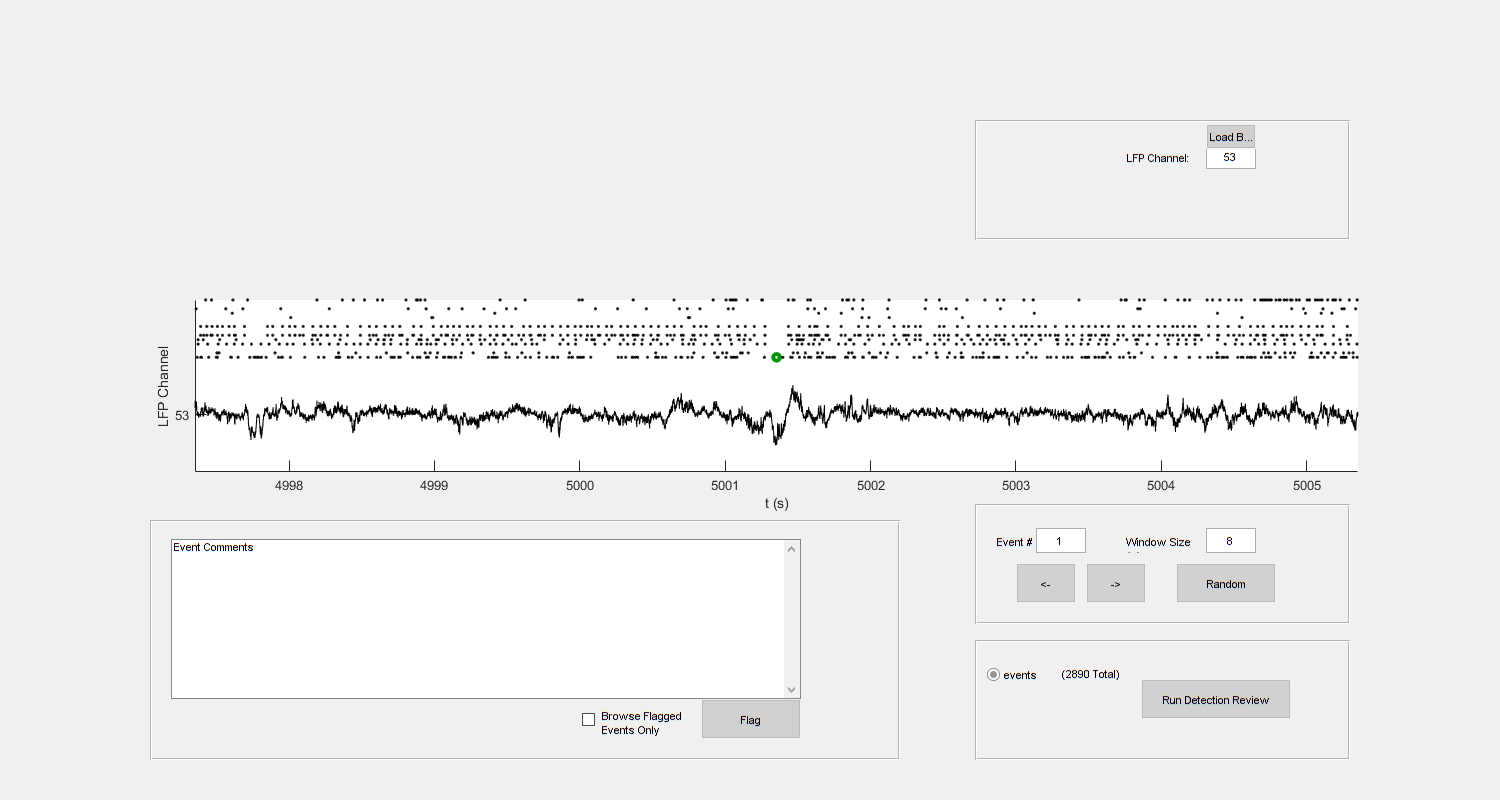

    JR_EventExplorer(basepath, SW, 'spikes', spikes, 'lfp', dropLFPChans(lfp, L5Chan))

combined = combineAcrossAnimals([Animal6556, Animal6556b, Animal6556c, Animal6556d, ...
    Animal6560, Animal6560b, Animal7149,  Animal7158, Animal7158b, Animal7158c,...
    Animal6575a, Animal6575b, Animal6576, Animal6692,...
    Animal6695]); % Animal7149b,
nSessions = 15;


combined.UPTransientRatio.NREMSpont(isinf(combined.UPTransientRatio.NREMSpont)) = nan;

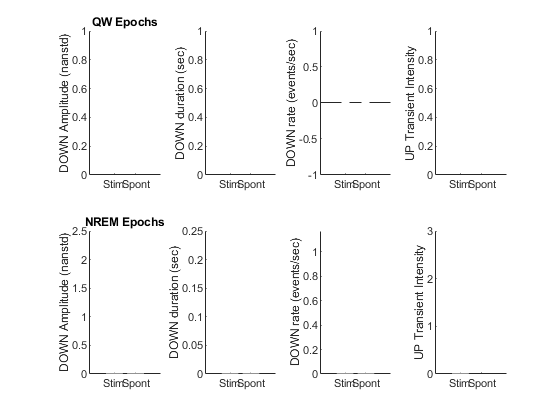

figure; subplot(2,4,1); hold on
bar([mean(combined.amplitude.QWStim) mean(combined.amplitude.QWSpont)],...
    'EdgeColor','none','FaceColor','w','FaceAlpha',.5)
errorbar([mean(combined.amplitude.QWStim) mean(combined.amplitude.QWSpont)],...
    [nanstd(combined.amplitude.QWStim) nanstd(combined.amplitude.QWSpont)]./sqrt(nSessions),...
    'LineStyle','none','Color','w','LineWidth',2)
xticks(1:2)
xticklabels({'Stim', 'Spont'})
ylabel('DOWN Amplitude (nanstd)')
title('QW Epochs')

subplot(2,4,2); hold on
bar([mean(combined.duration.QWStim) mean(combined.duration.QWSpont)],...
    'EdgeColor','none','FaceColor','w','FaceAlpha',.5)
errorbar([mean(combined.duration.QWStim) mean(combined.duration.QWSpont)],...
    [nanstd(combined.duration.QWStim) nanstd(combined.duration.QWSpont)]./sqrt(nSessions),...
    'LineStyle','none','Color','w','LineWidth',2)
xticks(1:2)
xticklabels({'Stim', 'Spont'})
ylabel('DOWN duration (sec)')

subplot(2,4,3); hold on
bar([mean(combined.rate.QWStim) mean(combined.rate.QWSpont)],...
    'EdgeColor','none','FaceColor','w','FaceAlpha',.5)
errorbar([mean(combined.rate.QWStim) mean(combined.rate.QWSpont)],...
    [nanstd(combined.rate.QWStim) nanstd(combined.rate.QWSpont)]./sqrt(nSessions),...
    'LineStyle','none','Color','w','LineWidth',2)
xticks(1:2)
xticklabels({'Stim', 'Spont'})
ylabel('DOWN rate (events/sec)')

subplot(2,4,4); hold on
bar([mean(combined.UPTransientRatio.QWStim) mean(combined.UPTransientRatio.QWSpont)],...
    'EdgeColor','none','FaceColor','w','FaceAlpha',.5)
errorbar([mean(combined.UPTransientRatio.QWStim) mean(combined.UPTransientRatio.QWSpont)],...
    [nanstd(combined.UPTransientRatio.QWStim) nanstd(combined.UPTransientRatio.QWSpont)]./sqrt(nSessions),...
    'LineStyle','none','Color','w','LineWidth',2)
xticks(1:2)
xticklabels({'Stim', 'Spont'})
ylabel('UP Transient Intensity')

subplot(2,4,5); hold on
bar([mean(combined.amplitude.NREMStim) mean(combined.amplitude.NREMSpont)],...
    'EdgeColor','none','FaceColor','w','FaceAlpha',.5)
errorbar([mean(combined.amplitude.NREMStim) mean(combined.amplitude.NREMSpont)],...
    [nanstd(combined.amplitude.NREMStim) nanstd(combined.amplitude.NREMSpont)]./sqrt(nSessions),...
    'LineStyle','none','Color','w','LineWidth',2)
xticks(1:2)
xticklabels({'Stim', 'Spont'})
ylabel('DOWN Amplitude (nanstd)')
title('NREM Epochs')

subplot(2,4,6); hold on
bar([mean(combined.duration.NREMStim) mean(combined.duration.NREMSpont)],...
    'EdgeColor','none','FaceColor','w','FaceAlpha',.5)
errorbar([mean(combined.duration.NREMStim) mean(combined.duration.NREMSpont)],...
    [nanstd(combined.duration.NREMStim) nanstd(combined.duration.NREMSpont)]./sqrt(nSessions),...
    'LineStyle','none','Color','w','LineWidth',2)
xticks(1:2)
xticklabels({'Stim', 'Spont'})
ylabel('DOWN duration (sec)')

subplot(2,4,7); hold on
bar([mean(combined.rate.NREMStim) mean(combined.rate.NREMSpont)],...
    'EdgeColor','none','FaceColor','w','FaceAlpha',.5)
errorbar([mean(combined.rate.NREMStim) mean(combined.rate.NREMSpont)],...
    [nanstd(combined.rate.NREMStim) nanstd(combined.rate.NREMSpont)]./sqrt(nSessions),...
    'LineStyle','none','Color','w','LineWidth',2)
xticks(1:2)
xticklabels({'Stim', 'Spont'})
ylabel('DOWN rate (events/sec)')

subplot(2,4,8); hold on
bar([mean(combined.UPTransientRatio.NREMStim) mean(combined.UPTransientRatio.NREMSpont)],...
    'EdgeColor','none','FaceColor','w','FaceAlpha',.5)
errorbar([mean(combined.UPTransientRatio.NREMStim) mean(combined.UPTransientRatio.NREMSpont)],...
    [nanstd(combined.UPTransientRatio.NREMStim) nanstd(combined.UPTransientRatio.NREMSpont)]./sqrt(nSessions),...
    'LineStyle','none','Color','w','LineWidth',2)
xticks(1:2)
xticklabels({'Stim', 'Spont'})
ylabel('UP Transient Intensity')

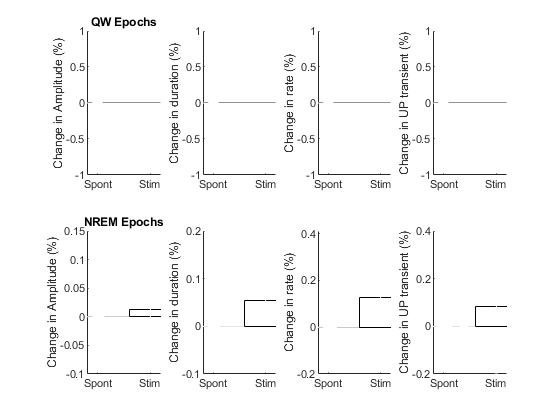

figure; subplot(2,4,1); hold on
plot([zeros(1,nSessions); combined.amplitude.QWStim./combined.amplitude.QWSpont-1],'wo--','LineWidth',2,'MarkerFaceColor','w')
xlim([.8 2.2])
plot(xlim, [0 0], 'w')
ylabel('Change in Amplitude (%)')
xticks(1:2)
xticklabels({'Spont', 'Stim'})
title('QW Epochs')

bar(2, mean(combined.amplitude.QWStim./combined.amplitude.QWSpont-1,'omitnan'),'FaceColor','none')
plot([2 2], mean(combined.amplitude.QWStim./combined.amplitude.QWSpont-1,'omitnan') + [-1 1] .* ... 
    std(combined.amplitude.QWStim./combined.amplitude.QWSpont-1,'omitnan')./sqrt(nSessions),'Color','w')

subplot(2,4,2); hold on
plot([zeros(1,nSessions); combined.duration.QWStim./combined.duration.QWSpont-1],'wo--','LineWidth',2,'MarkerFaceColor','w')
xlim([.8 2.2])
plot(xlim, [0 0], 'w')
ylabel('Change in duration (%)')
xticks(1:2)
xticklabels({'Spont', 'Stim'})

bar(2, mean(combined.duration.QWStim./combined.duration.QWSpont-1,'omitnan'),'FaceColor','none')
plot([2 2], mean(combined.duration.QWStim./combined.duration.QWSpont-1,'omitnan') + [-1 1] .* ... 
    std(combined.duration.QWStim./combined.duration.QWSpont-1,'omitnan')./sqrt(nSessions),'Color','w')

subplot(2,4,3); hold on
plot([zeros(1,nSessions); combined.rate.QWStim./combined.rate.QWSpont-1],'wo--','LineWidth',2,'MarkerFaceColor','w')
xlim([.8 2.2])
plot(xlim, [0 0], 'w')
ylabel('Change in rate (%)')
xticks(1:2)
xticklabels({'Spont', 'Stim'})

bar(2, mean(combined.rate.QWStim./combined.rate.QWSpont-1,'omitnan'),'FaceColor','none')
plot([2 2], mean(combined.rate.QWStim./combined.rate.QWSpont-1,'omitnan') + [-1 1] .* ... 
    std(combined.rate.QWStim./combined.rate.QWSpont-1,'omitnan')./sqrt(nSessions),'Color','w')

subplot(2,4,4); hold on
plot([zeros(1,nSessions); combined.UPTransientRatio.QWStim./combined.UPTransientRatio.QWSpont-1],'wo--','LineWidth',2,'MarkerFaceColor','w')
xlim([.8 2.2])
plot(xlim, [0 0], 'w')
ylabel('Change in UP transient (%)')
xticks(1:2)
xticklabels({'Spont', 'Stim'})

bar(2, mean(combined.UPTransientRatio.QWStim./combined.UPTransientRatio.QWSpont-1,'omitnan'),'FaceColor','none')
plot([2 2], mean(combined.UPTransientRatio.QWStim./combined.UPTransientRatio.QWSpont-1,'omitnan') + [-1 1] .* ... 
    std(combined.UPTransientRatio.QWStim./combined.UPTransientRatio.QWSpont-1,'omitnan')./sqrt(nSessions),'Color','w')

subplot(2,4,5); hold on
plot([zeros(1,nSessions); combined.amplitude.NREMStim./combined.amplitude.NREMSpont-1],'wo--','LineWidth',2,'MarkerFaceColor','w')
xlim([.8 2.2])
plot(xlim, [0 0], 'w')
ylabel('Change in Amplitude (%)')
xticks(1:2)
xticklabels({'Spont', 'Stim'})
title('NREM Epochs')

bar(2, mean(combined.amplitude.NREMStim./combined.amplitude.NREMSpont-1,'omitnan'),'FaceColor','none')
plot([2 2], mean(combined.amplitude.NREMStim./combined.amplitude.NREMSpont-1,'omitnan') + [-1 1] .* ... 
    std(combined.amplitude.NREMStim./combined.amplitude.NREMSpont-1,'omitnan')./sqrt(nSessions),'Color','w')

subplot(2,4,6); hold on
plot([zeros(1,nSessions); combined.duration.NREMStim./combined.duration.NREMSpont-1],'wo--','LineWidth',2,'MarkerFaceColor','w')
xlim([.8 2.2])
plot(xlim, [0 0], 'w')
ylabel('Change in duration (%)')
xticks(1:2)
xticklabels({'Spont', 'Stim'})

bar(2, mean(combined.duration.NREMStim./combined.duration.NREMSpont-1,'omitnan'),'FaceColor','none')
plot([2 2], mean(combined.duration.NREMStim./combined.duration.NREMSpont-1,'omitnan') + [-1 1] .* ... 
    std(combined.duration.NREMStim./combined.duration.NREMSpont-1,'omitnan')./sqrt(nSessions),'Color','w')

subplot(2,4,7); hold on
plot([zeros(1,nSessions); combined.rate.NREMStim./combined.rate.NREMSpont-1],'wo--','LineWidth',2,'MarkerFaceColor','w')
xlim([.8 2.2])
plot(xlim, [0 0], 'w')
ylabel('Change in rate (%)')
xticks(1:2)
xticklabels({'Spont', 'Stim'})

bar(2, mean(combined.rate.NREMStim./combined.rate.NREMSpont-1,'omitnan'),'FaceColor','none')
plot([2 2], mean(combined.rate.NREMStim./combined.rate.NREMSpont-1,'omitnan') + [-1 1] .* ... 
    std(combined.rate.NREMStim./combined.rate.NREMSpont-1,'omitnan')./sqrt(nSessions),'Color','w')

subplot(2,4,8); hold on
plot([zeros(1,nSessions); combined.UPTransientRatio.NREMStim./combined.UPTransientRatio.NREMSpont-1],'wo--','LineWidth',2,'MarkerFaceColor','w')
xlim([.8 2.2])
plot(xlim, [0 0], 'w')
ylabel('Change in UP transient (%)')
xticks(1:2)
xticklabels({'Spont', 'Stim'})

bar(2, mean(combined.UPTransientRatio.NREMStim./combined.UPTransientRatio.NREMSpont-1,'omitnan'),'FaceColor','none')
plot([2 2], mean(combined.UPTransientRatio.NREMStim./combined.UPTransientRatio.NREMSpont-1,'omitnan') + [-1 1] .* ... 
    std(combined.UPTransientRatio.NREMStim./combined.UPTransientRatio.NREMSpont-1,'omitnan')./sqrt(nSessions),'Color','w')

disp('t-test comparing DOWN smplitude across spont and stim:')

t-test comparing DOWN smplitude across spont and stim:


[h p] = ttest(combined.amplitude.NREMStim, combined.amplitude.NREMSpont) 

h = 0

p = 0.4958


disp('t-test comparing DOWN duration across spont and stim:')

t-test comparing DOWN duration across spont and stim:


[h p] = ttest(combined.duration.NREMStim, combined.duration.NREMSpont) 

h = 1

p = 0.0022


disp('t-test comparing DOWN rate across spont and stim:')

t-test comparing DOWN rate across spont and stim:


[h p] = ttest(combined.rate.NREMStim, combined.rate.NREMSpont) 

h = 1

p = 0.0226


disp('t-test comparing DOWN to UP transient across spont and stim:')

t-test comparing DOWN to UP transient across spont and stim:


[h p] = ttest(combined.UPTransientRatio.NREMStim, combined.UPTransientRatio.NREMSpont) 

h = 0

p = 0.0524

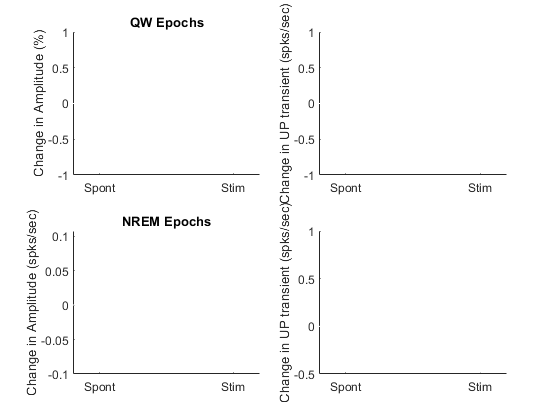

figure; subplot(2,2,1); hold on
plot([zeros(1,nSessions); combined.amplitude.QWStim./combined.amplitude.QWSpont-1],'wo--','LineWidth',2,'MarkerFaceColor','w')
xlim([.8 2.2])
plot(xlim, [0 0], 'w')
ylabel('Change in Amplitude (%)')
xticks(1:2)
xticklabels({'Spont', 'Stim'})
title('QW Epochs')

subplot(2,2,2); hold on
plot([zeros(1,nSessions); combined.UPTransientRatio.QWStim - combined.UPTransientRatio.QWSpont],'wo--','LineWidth',2,'MarkerFaceColor','w')
xlim([.8 2.2])
plot(xlim, [0 0], 'w')
ylabel('Change in UP transient (spks/sec)')
xticks(1:2)
xticklabels({'Spont', 'Stim'})

subplot(2,2,3); hold on
plot([zeros(1,nSessions); combined.amplitude.NREMStim ./ combined.amplitude.NREMSpont-1],'wo--','LineWidth',2,'MarkerFaceColor','w')
xlim([.8 2.2])
plot(xlim, [0 0], 'w')
ylabel('Change in Amplitude (spks/sec)')
xticks(1:2)
xticklabels({'Spont', 'Stim'})
title('NREM Epochs')

subplot(2,2,4); hold on
plot([zeros(1,nSessions); combined.UPTransientRatio.NREMStim - combined.UPTransientRatio.NREMSpont],'wo--','LineWidth',2,'MarkerFaceColor','w')
xlim([.8 2.2])
plot(xlim, [0 0], 'w')
ylabel('Change in UP transient (spks/sec)')
xticks(1:2)
xticklabels({'Spont', 'Stim'})

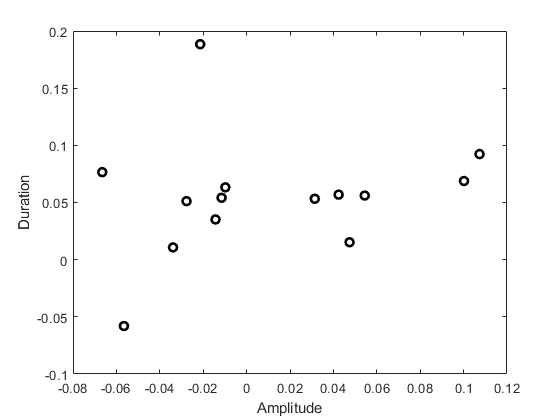

figure
plot(combined.amplitude.NREMStim./combined.amplitude.NREMSpont-1, combined.duration.NREMStim./combined.duration.NREMSpont-1,...
    'ko','LineWidth',2,'MarkerFaceColor','w','LineStyle','none')
ylabel('Duration')
xlabel('Amplitude')

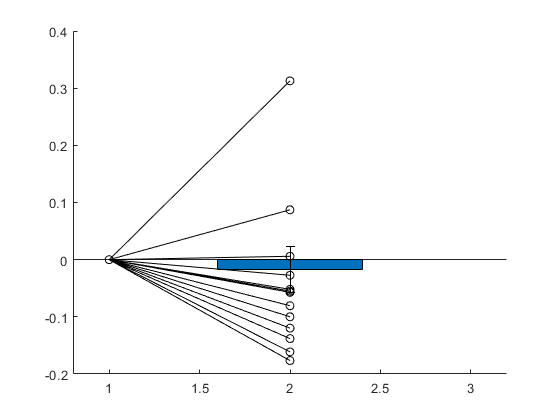

figure; hold on
combined.DOWNSpkSupr.NREMSpont(isinf(combined.DOWNSpkSupr.NREMSpont)) = nan;

bar(2, mean(combined.DOWNSpkSupr.NREMStim ./ combined.DOWNSpkSupr.NREMSpont, 'omitnan') - 1)
errorbar(2, mean(combined.DOWNSpkSupr.NREMStim ./ combined.DOWNSpkSupr.NREMSpont, 'omitnan') - 1,...
    std(combined.DOWNSpkSupr.NREMStim ./ combined.DOWNSpkSupr.NREMSpont, 'omitnan')/sqrt(nSessions),'k-')

plot([zeros(1,nSessions);...
    combined.DOWNSpkSupr.NREMStim ./ combined.DOWNSpkSupr.NREMSpont - 1],...
    'ko-')

[h, p] = ttest(combined.DOWNSpkSupr.NREMStim, combined.DOWNSpkSupr.NREMSpont)

h = 0

p = 0.3606

function output = combineAcrossAnimals(animals)

duration = struct();
amplitude = struct();
rate = struct();
UPTransientRatio = struct();
DOWNSpkSupr = struct();

conds = fieldnames(animals(1).ipsi.DOWNDuration);

for i = 1:length(animals)
    for j = 1:length(conds)
        duration.(conds{j})(i) = mean(animals(i).ipsi.DOWNDuration.(conds{j}));
        amplitude.(conds{j})(i) = mean(animals(i).ipsi.DOWNAmplitude.(conds{j}));
        rate.(conds{j})(i) = animals(i).ipsi.DOWNRate.(conds{j});
        UPTransientRatio.(conds{j})(i) = mean(animals(i).ipsi.UPTransRatio.(conds{j}));
        DOWNSpkSupr.(conds{j})(i) = mean(animals(i).ipsi.DOWNSupr.(conds{j}));
    end
end

output.duration = duration;
output.amplitude = amplitude;
output.rate = rate;
output.UPTransientRatio = UPTransientRatio;
output.DOWNSpkSupr = DOWNSpkSupr;

end

function output = analyzeDOWNStates(basepath, SW, spikes, optostim, optoInts)
[~, SWMask.QWStim] = RestrictInts(SW.timestamps, optoInts.QWStim);
[~, SWMask.QWSpont] = RestrictInts(SW.timestamps, optoInts.QWSpont);
[~, SWMask.NREMStim] = RestrictInts(SW.timestamps, optoInts.NREMStim);
[~, SWMask.NREMSpont] = RestrictInts(SW.timestamps, optoInts.NREMSpont);

output.DOWNDuration.QWStim = diff(SW.ints.DOWN(SWMask.QWStim,:),1,2);
output.DOWNDuration.QWSpont = diff(SW.ints.DOWN(SWMask.QWSpont,:),1,2);
output.DOWNDuration.NREMStim = diff(SW.ints.DOWN(SWMask.NREMStim,:),1,2);
output.DOWNDuration.NREMSpont = diff(SW.ints.DOWN(SWMask.NREMSpont,:),1,2);
output.DOWNAmplitude.QWStim = SW.SWpeakmag(SWMask.QWStim,:);
output.DOWNAmplitude.QWSpont = SW.SWpeakmag(SWMask.QWSpont,:);
output.DOWNAmplitude.NREMStim = SW.SWpeakmag(SWMask.NREMStim,:);
output.DOWNAmplitude.NREMSpont = SW.SWpeakmag(SWMask.NREMSpont,:);
output.DOWNRate.QWStim = sum(SWMask.QWStim)/sum(diff(optoInts.QWStim,1,2));
output.DOWNRate.QWSpont = sum(SWMask.QWSpont)/sum(diff(optoInts.QWSpont,1,2));
output.DOWNRate.NREMStim = sum(SWMask.NREMStim)/sum(diff(optoInts.NREMStim,1,2));
output.DOWNRate.NREMSpont = sum(SWMask.NREMSpont)/sum(diff(optoInts.NREMSpont,1,2));

% Look at relation between duration and amplitude for QW periods and NREM periods
ampEdges = 0:.25:8;
durEdges = 0:.05:1.5;

figure; subplot(3,3,2:3); hold on
histogram(output.DOWNDuration.QWStim,durEdges,'EdgeColor','none','FaceColor','b','Normalization','probability')
histogram(output.DOWNDuration.QWSpont,durEdges,'EdgeColor','none','FaceColor','w','Normalization','probability')
ylabel('Prob')
xlabel('DOWN state duration (sec)')
box off
set(gca, 'YAxisLocation', 'right')
xl1 = xlim;
title('QW DOWN states')
legend({'Stim', 'Spont'})

subplot(3,3,[4 7]); hold on
histogram(output.DOWNAmplitude.QWStim,ampEdges,'EdgeColor','none','FaceColor','b','Normalization','probability')
histogram(output.DOWNAmplitude.QWSpont,ampEdges,'EdgeColor','none','FaceColor','w','Normalization','probability')
ylabel('Count')
xlabel('DOWN state amplitude (nanstd devs)')
camroll(90)
box off
xl2 = xlim;

subplot(3,3,[5 6 8 9]); hold on
scatter(output.DOWNDuration.QWSpont, output.DOWNAmplitude.QWSpont, .1,'k.')
scatter(output.DOWNDuration.QWStim, output.DOWNAmplitude.QWStim, .1,'b.')
ylabel('DOWN state amplitude (nanstd devs)')
xlabel('DOWN state duration (sec)')
set(gca, 'YAxisLocation', 'right')
ylim(xl2)
xlim(xl1)

% For NREM periods
figure; subplot(3,3,2:3); hold on
histogram(output.DOWNDuration.NREMStim,durEdges,'EdgeColor','none','FaceColor','b','Normalization','probability')
histogram(output.DOWNDuration.NREMSpont,durEdges,'EdgeColor','none','FaceColor','w','Normalization','probability')
ylabel('Prob')
xlabel('DOWN state duration (sec)')
box off
set(gca, 'YAxisLocation', 'right')
xl1 = xlim;
title('NREM DOWN states')
legend({'Stim', 'Spont'})

subplot(3,3,[4 7]); hold on
histogram(output.DOWNAmplitude.NREMStim,ampEdges,'EdgeColor','none','FaceColor','b','Normalization','probability')
histogram(output.DOWNAmplitude.NREMSpont,ampEdges,'EdgeColor','none','FaceColor','w','Normalization','probability')
ylabel('Count')
xlabel('DOWN state amplitude (nanstd devs)')
camroll(90)
box off
xl2 = xlim;

subplot(3,3,[5 6 8 9]); hold on
scatter(output.DOWNDuration.NREMSpont, output.DOWNAmplitude.NREMSpont, .1,'k.')
scatter(output.DOWNDuration.NREMStim, output.DOWNAmplitude.NREMStim, .1,'b.')
ylabel('DOWN state amplitude (nanstd devs)')
xlabel('DOWN state duration (sec)')
set(gca, 'YAxisLocation', 'right')
ylim(xl2)
xlim(xl1)

% Plot means of these distributions
figure; subplot(2,3,1); hold on
bar([mean(output.DOWNDuration.QWStim) mean(output.DOWNDuration.QWSpont)],...
    'EdgeColor','none','FaceColor','w','FaceAlpha',.5)
errorbar([mean(output.DOWNDuration.QWStim) mean(output.DOWNDuration.QWSpont)],...
    [nanstd(output.DOWNDuration.QWStim) nanstd(output.DOWNDuration.QWSpont)]./sqrt(sum(SWMask.QWSpont)),...
    'LineStyle','none','Color','w','LineWidth',2)
xticks(1:2)
xticklabels({'Stim', 'Spont'})
ylabel('Duration')
% ylim([.2 .28])
title('QW DOWN Duration')

subplot(2,3,2); hold on
bar([mean(output.DOWNAmplitude.QWStim) mean(output.DOWNAmplitude.QWSpont)],...
    'EdgeColor','none','FaceColor','w','FaceAlpha',.5)
errorbar([mean(output.DOWNAmplitude.QWStim) mean(output.DOWNAmplitude.QWSpont)],...
    [nanstd(output.DOWNAmplitude.QWStim) nanstd(output.DOWNAmplitude.QWSpont)]./sqrt(sum(SWMask.QWSpont)),...
    'LineStyle','none','Color','w','LineWidth',2)
xticks(1:2)
xticklabels({'Stim', 'Spont'})
ylabel('Amp (nanstd)')
% ylim([2 2.5])
title('QW DOWN Amplitude')

subplot(2,3,4); hold on
bar([mean(output.DOWNDuration.NREMStim) mean(output.DOWNDuration.NREMSpont)],...
    'EdgeColor','none','FaceColor','w','FaceAlpha',.5)
errorbar([mean(output.DOWNDuration.NREMStim) mean(output.DOWNDuration.NREMSpont)],...
    [nanstd(output.DOWNDuration.NREMStim) nanstd(output.DOWNDuration.NREMSpont)]./sqrt(sum(SWMask.NREMSpont)),...
    'LineStyle','none','Color','w','LineWidth',2)
xticks(1:2)
xticklabels({'Stim', 'Spont'})
ylabel('Duration')
% ylim([.2 .28])
title('NREM DOWN Duration')

subplot(2,3,5); hold on
bar([mean(output.DOWNAmplitude.NREMStim) mean(output.DOWNAmplitude.NREMSpont)],...
    'EdgeColor','none','FaceColor','w','FaceAlpha',.5)
errorbar([mean(output.DOWNAmplitude.NREMStim) mean(output.DOWNAmplitude.NREMSpont)],...
    [nanstd(output.DOWNAmplitude.NREMStim) nanstd(output.DOWNAmplitude.NREMSpont)]./sqrt(sum(SWMask.NREMSpont)),...
    'LineStyle','none','Color','w','LineWidth',2)
xticks(1:2)
xticklabels({'Stim', 'Spont'})
ylabel('Amp (nanstd)')
% ylim([2 2.5])
title('NREM DOWN Amplitude')

% Look at rate of occurance of these states
subplot(2,3,6)
bar([output.DOWNRate.NREMStim output.DOWNRate.NREMSpont],...
    'EdgeColor','none','FaceColor','w','FaceAlpha',.5)
xticklabels({'Stim', 'Spont'})
ylabel('DOWN state rate (events/sec)')
box off
title('Event rate NREM')

subplot(2,3,3)
bar([output.DOWNRate.QWStim output.DOWNRate.QWSpont],...
    'EdgeColor','none','FaceColor','w','FaceAlpha',.5)
xticklabels({'Stim', 'Spont'})
ylabel('DOWN state rate (events/sec)')
box off
title('Event Rate QW')

% Look at how spiking changes around DOWN to UP transition
peth.QWStim = bz_PETH_Spikes(SW.ints.DOWN(SWMask.QWStim,2), 'basepath', basepath, 'cellnums', spikes.UID,...
    'secondsBefore',.1, 'secondsAfter',.5,'binWidth',.01,'plotting',0);
peth.QWSpont = bz_PETH_Spikes(SW.ints.DOWN(SWMask.QWSpont,2), 'basepath', basepath, 'cellnums', spikes.UID,...
    'secondsBefore',.1, 'secondsAfter',.5,'binWidth',.01,'plotting',0);
peth.NREMStim = bz_PETH_Spikes(SW.ints.DOWN(SWMask.NREMStim,2), 'basepath', basepath, 'cellnums', spikes.UID,...
    'secondsBefore',.1, 'secondsAfter',.5,'binWidth',.01,'plotting',0);
peth.NREMSpont = bz_PETH_Spikes(SW.ints.DOWN(SWMask.NREMSpont,2), 'basepath', basepath, 'cellnums', spikes.UID,...
    'secondsBefore',.1, 'secondsAfter',.5,'binWidth',.01,'plotting',0);

% Normalize to steady state FR
peth.QWStim.normrate = squeeze(mean(peth.QWStim.counts,1)) ./ squeeze(mean(mean(peth.QWStim.counts(:,45:60,:),1),2))';
peth.QWSpont.normrate = squeeze(mean(peth.QWSpont.counts,1)) ./ squeeze(mean(mean(peth.QWSpont.counts(:,45:60,:),1),2))';
peth.NREMStim.normrate = squeeze(mean(peth.NREMStim.counts,1)) ./ squeeze(mean(mean(peth.NREMStim.counts(:,45:60,:),1),2))';
peth.NREMSpont.normrate = squeeze(mean(peth.NREMSpont.counts,1)) ./ squeeze(mean(mean(peth.NREMSpont.counts(:,45:60,:),1),2))';


figure; subplot(2,2,1); hold on
peth.time = peth.QWSpont.relativeBins(1:end-1) + .005;
% plot(peth.time, squeeze(mean(mean(peth.QWStim.counts,1),3)),'b')
% plot(peth.time, squeeze(mean(mean(peth.QWSpont.counts,1),3)),'w')
plot(peth.time, mean(peth.QWStim.normrate,2),'b')
plot(peth.time, mean(peth.QWSpont.normrate,2),'w')
xlabel('Time (sec)')
ylabel('Firing rate')
title('QW DOWN state PSTH')
legend({'Stim','Spont'},'location','southeast')

subplot(2,2,3); hold on
% plot(peth.time, squeeze(mean(mean(peth.NREMStim.counts,1),3)),'b')
% plot(peth.time, squeeze(mean(mean(peth.NREMSpont.counts,1),3)),'w')
plot(peth.time, mean(peth.NREMStim.normrate,2),'b')
plot(peth.time, mean(peth.NREMSpont.normrate,2),'w')
xlabel('Time (sec)')
ylabel('Firing rate')
title('NREM DOWN state PSTH')
legend({'Stim','Spont'},'location','southeast')

peth.QWSpont.meanCounts = squeeze(mean(peth.QWSpont.counts,1));
peth.QWStim.meanCounts = squeeze(mean(peth.QWStim.counts,1));
peth.NREMSpont.meanCounts = squeeze(mean(peth.NREMSpont.counts,1));
peth.NREMStim.meanCounts = squeeze(mean(peth.NREMStim.counts,1));

transWin = peth.time < .1;
steadWin = peth.time > .1 & peth.time < .2;
UPTransRatio.QWSpont = max(peth.QWSpont.normrate(transWin,:),[],1) ./ mean(peth.QWSpont.normrate(steadWin,:),1);
UPTransRatio.QWStim = max(peth.QWStim.normrate(transWin,:),[],1) ./ mean(peth.QWStim.normrate(steadWin,:),1);
UPTransRatio.NREMSpont = max(peth.NREMSpont.normrate(transWin,:),[],1) ./ mean(peth.NREMSpont.normrate(steadWin,:),1);
UPTransRatio.NREMStim = max(peth.NREMStim.normrate(transWin,:),[],1) ./ mean(peth.NREMStim.normrate(steadWin,:),1);

output.UPTransRatio = UPTransRatio;

DOWNwin = peth.time < 0
DOWNSupr.QWStim = squeeze(mean(mean(peth.QWStim.counts(:,DOWNwin,:),1),2)) ./ squeeze(mean(mean(peth.QWStim.counts(:,steadWin,:),1),2));
DOWNSupr.QWSpont = squeeze(mean(mean(peth.QWSpont.counts(:,DOWNwin,:),1),2)) ./ squeeze(mean(mean(peth.QWSpont.counts(:,steadWin,:),1),2));
DOWNSupr.NREMStim = squeeze(mean(mean(peth.NREMStim.counts(:,DOWNwin,:),1),2)) ./ squeeze(mean(mean(peth.NREMStim.counts(:,steadWin,:),1),2));
DOWNSupr.NREMSpont = squeeze(mean(mean(peth.NREMSpont.counts(:,DOWNwin,:),1),2)) ./ squeeze(mean(mean(peth.NREMSpont.counts(:,steadWin,:),1),2));

output.DOWNSupr = DOWNSupr;

subplot(2,2,2); hold on
bar([mean(UPTransRatio.QWStim) mean(UPTransRatio.QWSpont)],...
    'EdgeColor','none','FaceColor','w','FaceAlpha',.5)
errorbar([mean(UPTransRatio.QWStim) mean(UPTransRatio.QWSpont)], ...
    [nanstd(UPTransRatio.QWStim) nanstd(UPTransRatio.QWSpont)]./sqrt(spikes.numcells),...
    'LineStyle','none','Color','w','LineWidth',2)
xticks(1:2)
xticklabels({'Stim','Spont'})
ylabel('UP Transient Intesity')
% ylim([1 2.5])
title('QW')

subplot(2,2,4); hold on
bar([mean(UPTransRatio.NREMStim) mean(UPTransRatio.NREMSpont)],...
    'EdgeColor','none','FaceColor','w','FaceAlpha',.5)
errorbar([mean(UPTransRatio.NREMStim) mean(UPTransRatio.NREMSpont)], ...
    [nanstd(UPTransRatio.NREMStim) nanstd(UPTransRatio.NREMSpont)]./sqrt(spikes.numcells),...
    'LineStyle','none','Color','w','LineWidth',2)
xticks(1:2)
xticklabels({'Stim','Spont'})
ylabel('UP Transient Intesity')
% ylim([1 2.5])
title('NREM')
end

function optoInts = getOptoInts(basepath, optostim, threshold)

basename = bz_BasenameFromBasepath(basepath);

% Load state information
facemotion = extractArousalState(basepath);

% Get state intervals
load(fullfile(basepath,basename + ".SleepState.states.mat"),"SleepState")
stateInts.NREM = SleepState.ints.NREMstate;
stateInts.REM = SleepState.ints.REMstate;
stateInts.WAKE = SleepState.ints.WAKEstate;
stateInts.moveInts = facemotion.time(SSTnNOS.defMovementIntervals(facemotion.motionSmooth', threshold, 1));
[~, sleepMask] = RestrictInts(stateInts.moveInts, [stateInts.REM; stateInts.NREM]);
stateInts.moveInts(sleepMask,:) = [];
stateInts.stillInts = [stateInts.moveInts(1:end-1,2) stateInts.moveInts(2:end,1)];
stateInts.stillInts = stateInts.stillInts(diff(stateInts.stillInts,1,2) > 20,:); % For stillness
stateInts.QWInts = IntersectIntervals(stateInts.WAKE, stateInts.stillInts); % For stillness w/o sleep

% Get state and stim intervals
optoInts.NREMStim = IntersectIntervals(stateInts.NREM, optostim.longStimInts);
optoInts.NREMSpont = IntersectIntervals(stateInts.NREM, optostim.spontInts);
optoInts.REMStim = IntersectIntervals(stateInts.REM, optostim.longStimInts);
optoInts.REMSpont = IntersectIntervals(stateInts.REM, optostim.spontInts);
optoInts.MoveStim = IntersectIntervals(stateInts.moveInts, optostim.longStimInts);
optoInts.MoveSpont = IntersectIntervals(stateInts.moveInts, optostim.spontInts);
optoInts.QWStim = IntersectIntervals(stateInts.QWInts, optostim.longStimInts);
optoInts.QWSpont = IntersectIntervals(stateInts.QWInts, optostim.spontInts);

end

function lfpOut = dropLFPChans(lfp,keepChan)

channelSelectionMask = ismember(lfp.channels, keepChan);
lfp.channels = lfp.channels(channelSelectionMask);
lfp.data = lfp.data(:,channelSelectionMask);
lfp.region = lfp.region(channelSelectionMask);

lfpOut = lfp;

end